# Matlab live script for analyzing ultrasound-evoked escape responses.

This Matlab script is to process the DLC(DeepLabCut) data for the ultrasound-evoked egocentric escape trials using the Barnes Maze. 

Before running the script select the folder you want to access files from. To do this click the "open" in the top bar select your desired folder. 

From the "Live Editor" tab in MATLAB click the "Run" button. This should start the script from the beginning and move to the end prompting you when you need to feed different files into the program.

If the "Life Editor" tab is not visible click into one of the script boxes and it should appear.

You wil require the following files to run this code:

- CSV file created by the DLC.

- Bonsai XY file created by Bonsai during testing.

- Ultrasound onset (in seconds) - calculated based on the keystroke timestamps file and the start timestamp in the Bonsai XY file which are both created by Bonsai during testing.

- Video file used in the DLC.

clear all;close all;clc;

## Import DLC data

Import raw DLC data as table

% Step 1: Use dir to find the file starting with 'Video'
fileInfoDLC = dir('Video*.csv'); % Looks for files starting with 'Video' and ending with '.csv'

% Step 2: Check if any files were found
if ~isempty(fileInfoDLC)
    % Step 3: Get the file name and path
    fileNameDLC = fileInfoDLC(1).name; % Name of the first matching file
    pathNameDLC = fileInfoDLC(1).folder; % Path where the file is located

    % Step 4: Construct the full file path
    fullFilePathDLC = fullfile(pathNameDLC, fileNameDLC);

    % Step 5: Import the CSV file
    dataDLC = readtable(fullFilePathDLC); % Read the CSV file into a table

    % Display the file name and path
    disp(['File Name DLC: ', fileNameDLC]);
    disp(['Path Name DLC: ', pathNameDLC]);
else
    disp('No files starting with "Video" were found.');
end

File Name DLC: Video2025-05-27T11_42_54DLC_resnet50_InfraredCameraJan26shuffle1_600000.csv


Path Name DLC: C:\Users\kandy\OneDrive - University of Toronto\UofT\Experiments\Nts-Cre (MM) Experiments\Nts-Cre (MM) Optogenetics Experiments\Path Integration Opto\Bilateral implant MM\89-3\89-3 Laser Off



opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["scorer", "nose_x", "nose_y", "nose_accuracy", "centre_x", "centre_y", "centre_accuracy", "tail_x", "tail_y", "tail_accuracy", "shelter_x", "shelter_y", "shelter_accuracy"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
azopts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DLCraw = readtable(fullfile(pathNameDLC,fileNameDLC),opts);
clear opts

## Import Bonsai XY

Import raw Bonsai xy data as table

% Step 1: Use dir to find the file starting with 'Video'
fileInfoBonsai = dir('Bonsai*.csv'); % Looks for files starting with 'Video' and ending with '.csv'

% Step 2: Check if any files were found
if ~isempty(fileInfoBonsai)
    % Step 3: Get the file name and path
    fileNameBonsai = fileInfoBonsai(1).name; % Name of the first matching file
    pathNameBonsai = fileInfoBonsai(1).folder; % Path where the file is located

    % Step 4: Construct the full file path
    fullFilePathBonsai = fullfile(pathNameBonsai, fileNameBonsai);

    % Step 5: Import the CSV file
    dataBonsai = readtable(fullFilePathBonsai); % Read the CSV file into a table

    % Display the file name and path
    disp(['File Name Bonsai: ', fileNameBonsai]);
    disp(['Path Name Bonsai: ', pathNameBonsai]);
else
    disp('No files starting with "Video" were found.');
end

File Name Bonsai: BonsaiXY2025-05-27T11_42_51.csv


Path Name Bonsai: C:\Users\kandy\OneDrive - University of Toronto\UofT\Experiments\Nts-Cre (MM) Experiments\Nts-Cre (MM) Optogenetics Experiments\Path Integration Opto\Bilateral implant MM\89-3\89-3 Laser Off



opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timestampmiliseconds", "x", "y"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
BonsaiXY = readtable(fullfile(pathNameBonsai,fileNameBonsai),opts);
clear opts

BonsaiXY.timestamp = (BonsaiXY.timestampmiliseconds(:,1)-BonsaiXY.timestampmiliseconds(1,1))/1000;

## Calculate the timpoints of the ultrasound keypress

Import the first column of KeyDown data

% Get list of all CSV files in the directory
allFiles = dir('*.csv');

% Find file(s) that start with 'KeyDown'
keyDownFile = allFiles(startsWith({allFiles.name}, 'KeyDown'));

% Check if any matching file is found
if ~isempty(keyDownFile)
    % Load the first matching file
    fileName = keyDownFile(1).name;
    data = readtable(fileName);

    % Assign the first column to KeyPress variable
    KeyPress = data{:, 1};

    % Load BonsaiXY file (assumes it is in the same directory)
    bonsaiFile = allFiles(contains({allFiles.name}, 'BonsaiXY'));
    if ~isempty(bonsaiFile)
        bonsaiData = readtable(bonsaiFile(1).name);
        firstValue = bonsaiData{1, 1}; % First row, first column value

        % Transform KeyPress data
        KeyPress = (KeyPress - firstValue) / 1000;

        % Convert KeyPress to array with values across the first row
        ks = KeyPress';
    else
        error('BonsaiXY file not found in the directory.');
    end
else
    error('No file starting with "KeyDown" found in the directory.');
end

### Equalize the Number of Rows from BonsaiXY and DLCraw to combine both files

% Equalize the row numbers.
Min = min([height(BonsaiXY),height(DLCraw)]);
BonsaiXY = BonsaiXY(1:Min,:);DLCraw = DLCraw(1:Min,:);

DLCraw.timestamp = BonsaiXY.timestamp;

DLCraw = movevars(DLCraw, 'timestamp', "Before", 'scorer');

## **Select and Plot the Shelter & Platform**

Define the shelter in two steps:

- Click the centre of the shelter/platform

- Drag to identify the perimeter of the shelter/platform

If you are unsure where the shelter is because it is not very clear in the image, go into the folder in the computer to look at the raw video to see where the animal goes inside.

If you do not think you correcly identifed the shelter or had issues outlining the shelter's perimeter stop MATLAB by pressing the "Stop" button (top right of the Live Editor tab).

Re run the code by clicking your cursor at the beginning of this code block and then click the "Run to End" button to restart the code from here. DO NOT click "Run" as this will restart the code from the beginning.

## Import Video

Import video file

% Step 1: Use dir to find the file starting with 'Video'
fileInfoVideo = dir('Video*.avi'); % Looks for files starting with 'Video' and ending with '.csv'

% Step 2: Check if any files were found
if ~isempty(fileInfoVideo)
    % Step 3: Get the file name and path
    fileNameVideo = fileInfoVideo(1).name; % Name of the first matching file
    pathNameVideo = fileInfoVideo(1).folder; % Path where the file is located

    videoObject = VideoReader(fullfile(pathNameVideo,fileNameVideo));

    % Display the file name and path
    disp(['File Name Video: ', fileNameVideo]);
    disp(['Path Name Video: ', pathNameVideo]);
else
    disp('No files starting with "Video" were found.');
end

File Name Video: Video2025-05-27T11_42_54.avi


Path Name Video: C:\Users\kandy\OneDrive - University of Toronto\UofT\Experiments\Nts-Cre (MM) Experiments\Nts-Cre (MM) Optogenetics Experiments\Path Integration Opto\Bilateral implant MM\89-3\89-3 Laser Off



frame = read(videoObject,300); %frame will be used to define the shelter location

Shelter Info

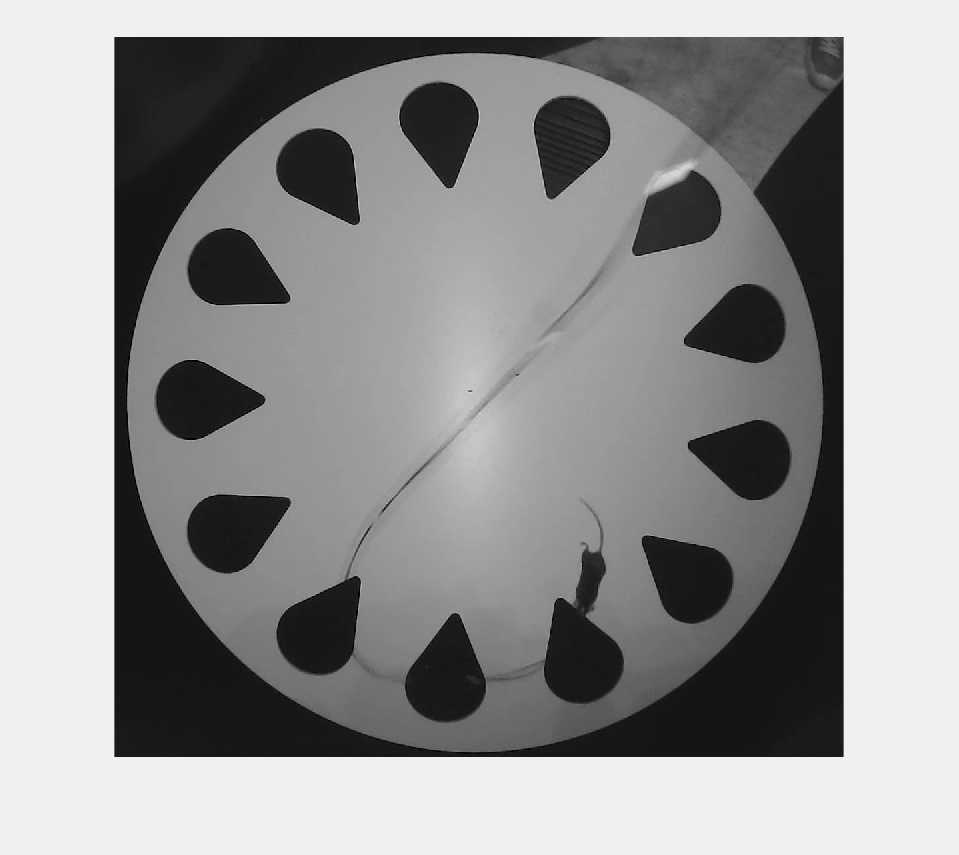

close all
imshow(frame);
[shelter_x,shelter_y] = ginput(1);

% ROI = drawcircle('LineWidth',0.5,'StripeColor','cyan','Label','Shelter Zone');
% shelter_r = ROI.Radius; % radius of shelter roi in pixel.
shelter_r = 85

shelter_r = 85

Shift LED Info

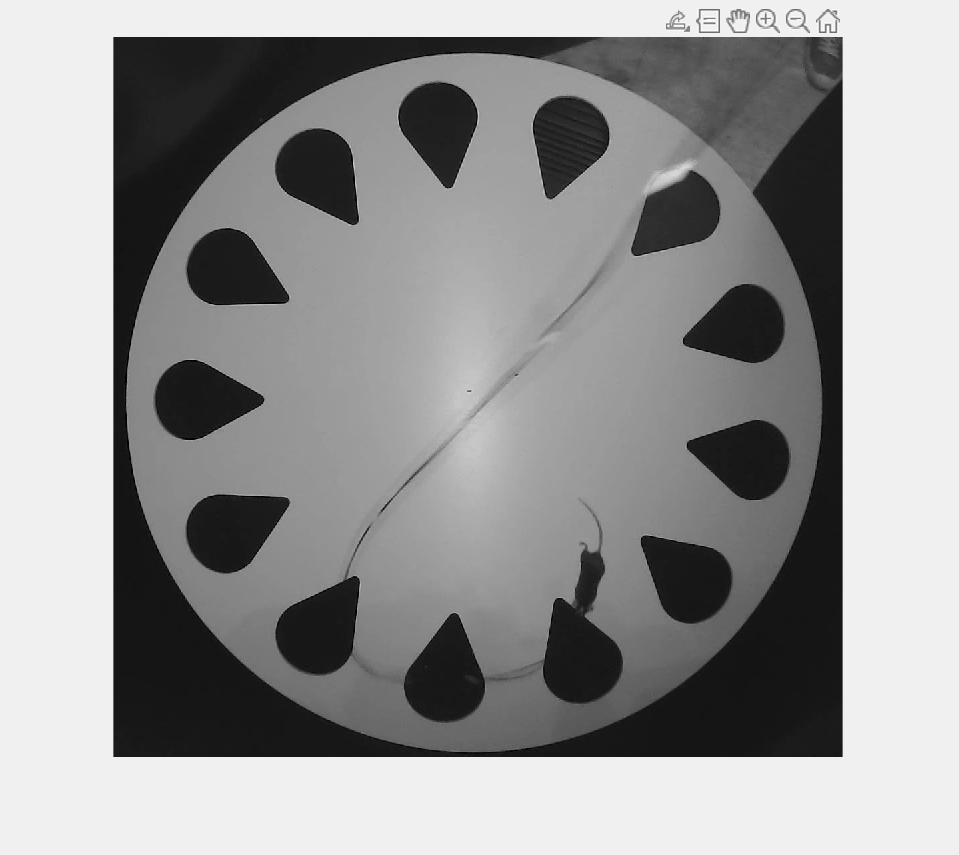

imshow(frame);
[shiftLED_x,shiftLED_y] = ginput(1);

% ROI = drawcircle('LineWidth',0.5,'StripeColor','cyan','Label','Shelter Zone');
% shelter_r = ROI.Radius; % radius of shelter roi in pixel.
shiftLED_r = 85

shiftLED_r = 85

Platform Info

% imshow(frame);
% ROI = drawcircle('LineWidth',0.5,'StripeColor','red','Label','Platform Zone');
% platform_r = ROI.Radius; % radius of platform roi in pixel.
platform_r = 535

platform_r = 535

% close

% Step 2: Get image dimensions
[rows, cols, ~] = size(frame);

% Step 3: Calculate the center point
platform_x = cols / 2;
platform_y = rows / 2;

close

Pixels per meter conversion

Width of the shelter hole is 10 cm in real life.

Width of the shelter hole in pixels is shelter_r.

%divide shelter_r by 10 cm to get pixels/cm
pixelspercm = shelter_r/10;
%multiple pixelspercm by 100 to get pixels/m
pixelsperm = pixelspercm*100;

## Refine the DLC data

### Fill in missing low accuracy DLC data

acc_threshold = 0.8;
error_noseIDX = find(DLCraw.nose_accuracy < acc_threshold);
DLCraw.nose_x(error_noseIDX) = NaN;
DLCraw.nose_y(error_noseIDX) = NaN;
DLCraw.nose_x = fillmissing(DLCraw.nose_x,"nearest");
DLCraw.nose_y = fillmissing(DLCraw.nose_y,"nearest");

error_tailIDX = find(DLCraw.tail_accuracy < acc_threshold);
DLCraw.tail_x(error_tailIDX) = NaN;
DLCraw.tail_y(error_tailIDX) = NaN;
DLCraw.tail_x = fillmissing(DLCraw.tail_x,"nearest");
DLCraw.tail_y = fillmissing(DLCraw.tail_y,"nearest");

error_centreIDX = find(DLCraw.centre_accuracy < acc_threshold);
DLCraw.centre_x(error_tailIDX) = NaN;
DLCraw.centre_y(error_tailIDX) = NaN;
DLCraw.centre_x = fillmissing(DLCraw.centre_x,"nearest");
DLCraw.centre_y = fillmissing(DLCraw.centre_y,"nearest");

### If the accuracy of DLC tracking is below a set threshold, we assume that the mouse body position is same as the shelter position. 

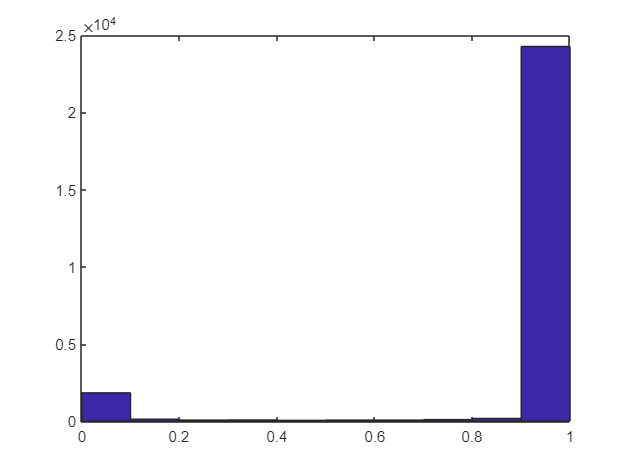

nose_acc = DLCraw.nose_accuracy;
hist(nose_acc)

nose_acc_threshold = 0.6;
error_noseIDX = find(DLCraw.nose_accuracy < nose_acc_threshold);
DLCraw.nose_x(error_noseIDX) = shelter_x;
DLCraw.nose_y(error_noseIDX) = shelter_y;
DLCraw.centre_x(error_noseIDX) = shelter_x;
DLCraw.centre_y(error_noseIDX) = shelter_y;
DLCraw.tail_x(error_noseIDX) = shelter_x;
DLCraw.tail_y(error_noseIDX) = shelter_y;
DLCraw;

### If points are outside the defined platform ROI, we assume the mouse body position is the same as the shelter position. 

Platform boundary outside which points are being updated to the shelter centre

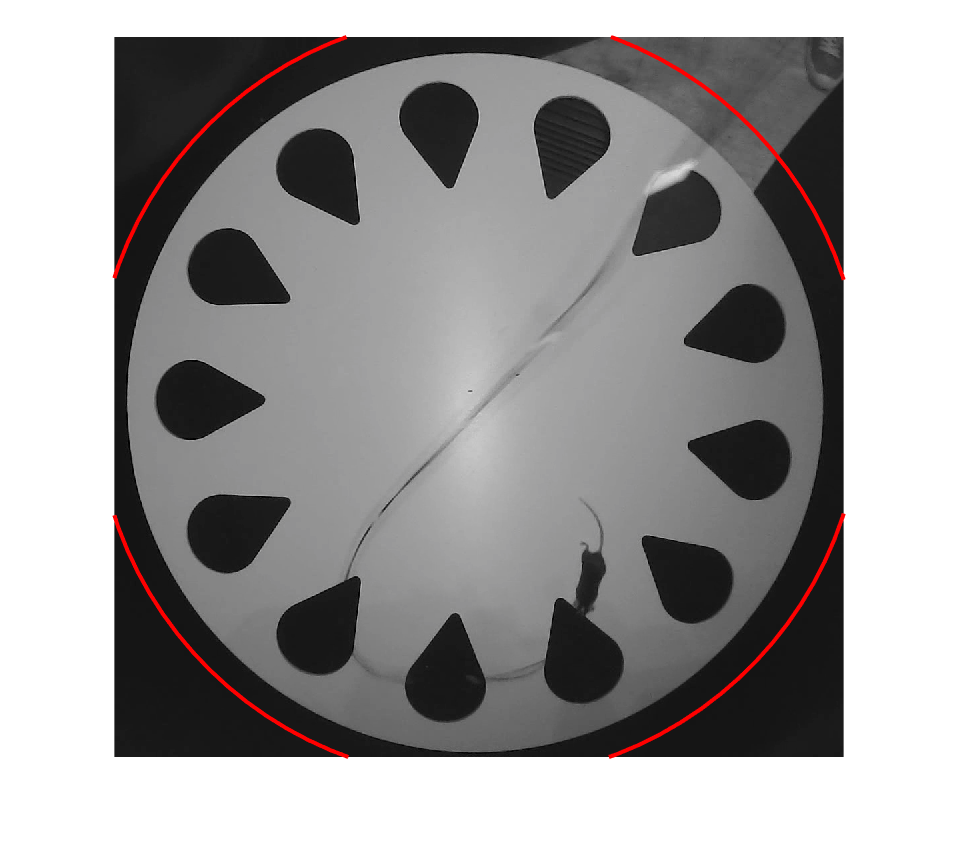

% Display the image
figure;
imshow(frame);
hold on;

% Draw the circle
theta = linspace(0, 2*pi, 100);
x_circle = platform_x + (platform_r + 40)* cos(theta);
y_circle = platform_y + (platform_r + 40)* sin(theta);
plot(x_circle, y_circle, 'r-', 'LineWidth', 2); 

Centre points

% Calculate the distance of each point from the center of the circle
centre_distances = sqrt((DLCraw.centre_x - platform_x).^2 + (DLCraw.centre_y - platform_y).^2);

% Find the indices of points outside the circle
centreoutside_indices = centre_distances > platform_r + 40;

% Change coordinates outside the circle to shelter coordinates
DLCraw.centre_x(centreoutside_indices) = shelter_x;
DLCraw.centre_y(centreoutside_indices) = shelter_y;

Nose points

% Calculate the distance of each point from the center of the circle
nose_distances = sqrt((DLCraw.nose_x - platform_x).^2 + (DLCraw.nose_y - platform_y).^2);

% Find the indices of points outside the circle
noseoutside_indices = nose_distances > platform_r + 40;

% Change coordinates outside the circle to shelter coordinates
DLCraw.nose_x(noseoutside_indices) = shelter_x;
DLCraw.nose_y(noseoutside_indices) = shelter_y;

Tail points

% Calculate the distance of each point from the center of the circle
tail_distances = sqrt((DLCraw.tail_x - platform_x).^2 + (DLCraw.tail_y - platform_y).^2);

% Find the indices of points outside the circle
tailoutside_indices = tail_distances > platform_r + 40;

% Change coordinates outside the circle to shelter coordinates
DLCraw.tail_x(tailoutside_indices) = shelter_x;
DLCraw.tail_y(tailoutside_indices) = shelter_y;

### Create a timetable from the DLC data.

DLCdata = table(DLCraw.nose_x, DLCraw.nose_y,'VariableNames', {'nose_x', 'nose_y'});
DLCdata.centre_x = DLCraw.centre_x;
DLCdata.centre_y = DLCraw.centre_y;
DLCdata.tail_x = DLCraw.tail_x;
DLCdata.tail_y = DLCraw.tail_y;
DLCdata.Time = DLCraw.timestamp;

DLCdata;

### Add additional features to the timetable

nose = [DLCdata.nose_x DLCdata.nose_y];
tail = [DLCdata.tail_x DLCdata.tail_y];
centre = [DLCdata.centre_x DLCdata.centre_y];
shelter (1:length(nose),1) = shelter_x;
shelter (1:length(nose),2) = shelter_y;

% calculate distance between tail and object(e.g., shelter).
x_t2o = shelter(:,1) - tail(:,1);
y_t2o = shelter(:,2) - tail(:,2);
t2o = sqrt( x_t2o.^2 + y_t2o.^2 );

% calculate distance between tail and nose.
x_t2n = nose(:,1) - tail(:,1);
y_t2n = nose(:,2) - tail(:,2);
t2n = sqrt( x_t2n.^2 + y_t2n.^2 );

% calculate distance between centre and object(e.g., shelter)  -- this is A.
x_c2o = shelter(:,1) - centre(:,1);
y_c2o = shelter(:,2) - centre(:,2);
c2o = sqrt( x_c2o.^2 + y_c2o.^2 );

% calculate distance between centre and nose -- this is B.
x_c2n = nose(:,1) - centre(:,1);
y_c2n = nose(:,2) - centre(:,2);
c2n = sqrt( x_c2n.^2 + y_c2n.^2 );

% calculate distance between nose and object(e.g., shelter) -- this is C.
x_n2o = shelter(:,1) - nose(:,1);
y_n2o = shelter(:,2) - nose(:,2);
n2o = sqrt( x_n2o.^2 + y_n2o.^2 );

% calculate the angle between line a and line b when given the length of connecting line c. cos(theta) = (a^2 + b^2 - c^2)/(2*a*b)
A = c2o;
B = c2n;
C = n2o;
X = (A.^2 + B.^2 - C.^2)./(2.*A.*B);
theta = rad2deg(acos(X)); % the angle column.

% calculate the speed of nose point
clear x y;
v_nose = [];
v_nose(1) = 0;
x = nose(:,1);
y = nose(:,2);
for ii = 2:length(nose)
    v_nose(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_nose = v_nose';

% calculate the speed of centre point
clear x y;
v_centre = [];
v_centre(1) = 0;
x = centre(:,1);
y = centre(:,2);
for ii = 2:length(centre)
    v_centre(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_centre = v_centre';

% calculate the speed of tail point
clear x y;
v_tail = [];
v_tail(1) = 0;
x = tail(:,1);
y = tail(:,2);
for ii = 2:length(tail)
    v_tail(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_tail = v_tail';

%% v_nose - v_tail may reflect sniffing
diff_v = v_nose - v_tail;

% add new feature columns to the timetable.
DLCdata.n2o = n2o;
DLCdata.t2n = t2n;
DLCdata.t2o = t2o;
DLCdata.c2o = c2o;
DLCdata.c2n = c2n;
DLCdata.theta = theta;
DLCdata.v_nose = v_nose;
DLCdata.v_centre = v_centre;
DLCdata.v_tail = v_tail;
DLCdata.diff_v = diff_v;

% add shelter event columns to the timetable.
event_true = (c2o < shelter_r);
event_dur = [];
for ii = 1:size(event_true,2)
    A = event_true(:,ii);
    out = double(diff([~A(1);A(:)]) == 1);
    v = accumarray(cumsum(out).*A(:)+1,1);
    out(out == 1) = v(2:end);
    event_dur(:,ii) = out;
end
DLCdata.event_true = event_true;
DLCdata.event_dur = event_dur;

% add shelter r, x and y, cue onsets columns.
DLCdata.shelter_r(:) = shelter_r;
DLCdata.shelter_x(:) = shelter_x;
DLCdata.shelter_y(:) = shelter_y;
fps = 1/mean(diff(DLCdata.Time));
DLCdata.fps(:) = fps;

for k = 1:length(ks)
    name = strcat('cueonset',num2str(k));
    DLCdata.(name)(:) = ks(k);
end

DLCdata

DLCdata = 26881×27 table
    nose_x    nose_y    centre_x    centre_y    tail_x    tail_y      Time       n2o       t2n       t2o       c2o       c2n      theta     v_nose     v_centre    v_tail      diff_v     event_true    event_dur    shelter_r    shelter_x    shelter_y     fps      cueonset1    cueonset2    cueonset3    cueonset4
    ______    ______    ________    ________    ______    ______    ________    

### Add shelter & platform variables to DLCdata

numRows = height(DLCdata);
DLCdata.shelter_r(:) = repmat(shelter_r, numRows, 1);
DLCdata.shelter_x(:) = repmat(shelter_x, numRows, 1);
DLCdata.shelter_y(:) = repmat(shelter_y, numRows, 1);
DLCdata.platform_r(:) = repmat(platform_r, numRows, 1);
DLCdata.platform_x(:) = repmat(platform_x, numRows, 1);
DLCdata.platform_y(:) = repmat(platform_y, numRows, 1);

DLCdata

DLCdata = 26881×30 table
    nose_x    nose_y    centre_x    centre_y    tail_x    tail_y      Time       n2o       t2n       t2o       c2o       c2n      theta     v_nose     v_centre    v_tail      diff_v     event_true    event_dur    shelter_r    shelter_x    shelter_y     fps      cueonset1    cueonset2    cueonset3    cueonset4    platform_r    platform_x    platform_y
    ______    ______    ________    ________

## Create trial events around ultrasound cue onsets.

Extract 240 rows for each escape (24 before ultrasound onset, 1 at ultrasound onset and 336 after ultrasound onset).

bl = 24; %number of data points to capture before event onset
seg_dur = 336; %number of data points to capture after event onset

Create a data table for trial events

% clear event_X ndistance distance speed theta tail_x tail_y nose_x nose_y
event_X = {}; % save all event data in a cell array
for k = 1:length(ks)
    temp = find(DLCdata.Time >= ks(k)); %find all data indices that are greater than or equal to keystroke timestamp
    event_X{k} = DLCdata(temp-bl:temp+seg_dur,:);
end

event_X

event_X = 1×4 cell array
    {361×30 table}    {361×30 table}    {361×30 table}    {361×30 table}


## Remove incorrect tracking points outside the platform perimeter

outside_width = 20;

% Calculate the distance from the center of the circle for each coordinate
distances = sqrt((DLCdata.centre_x - DLCdata.platform_x).^2 + (DLCdata.centre_y - DLCdata.platform_y).^2);

% Identify the indices of the points outside the radius defined by platform_r
outside_indices = distances > platform_r + outside_width;

% Get the coordinates that are outside the radius
outside_centre_x = DLCdata.centre_x(outside_indices);
outside_centre_y = DLCdata.centre_y(outside_indices);

% %plot points outside the platform perimeter
% fighandle = figure;
%     theta = linspace(0,2*pi);
%     platform_x = platform_r*cos(theta) + platform_x;
%     platform_y = platform_r*sin(theta) + platform_y;
%     plot(platform_x,platform_y,'color', "#55A0FB", 'linewidth', 2);
% 
%     hold on
% 
%  plot(outside_centre_x, outside_centre_y, 'k');
%     hold on
% 
% keyboard

%identify indices with points outside the platform perimeter
Indices = find(outside_indices)

Indices =         1440
        7567
        7569
        7570
        7571
        7572
        7573
        7574
        7575
        7576



%replace data at the identified indices with NaN
DLCdata.centre_x(Indices) = NaN;
DLCdata.centre_y(Indices) = NaN;

%fill data at the identified indices with linear interpolation
DLCdata.centre_x = fillmissing(DLCdata.centre_x,'linear');
DLCdata.centre_y = fillmissing(DLCdata.centre_y,'linear');

### Identify and replace points where DLC had issues tracking by looking centre_x and centre_y data.

centre_x

% fill missing datapoints
for n = 1:length(event_X)
    missingcentre_x = fillmissing(event_X{n}.centre_x,'linear');
    event_X{n}.centre_x = missingcentre_x;
end

% identify centre_x outliers
centre_xoutliers = [];

for k = 1:length(ks)
    centre_xoutliers(:,k) = isoutlier(event_X{k}.centre_x,"movmedian",[5 5]);
end

% compile original DLC tracking data
originalcentre_x =[];
for k = 1:length(ks)
    originalcentre_x(:,k) = event_X{k}.centre_x;
end
close all

% compile corrected DLC tracking data
centre_xcorrected = [];

for k = 1:length(ks)
    centre_xcorrected(:,k) = filloutliers(event_X{k}.centre_x,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end


centre_y

% fill missing datapoints
for n = 1:length(event_X)
    missingcentre_y = fillmissing(event_X{n}.centre_y,'linear');
    event_X{n}.centre_y = missingcentre_y;
end

% identify centre_y outliers
centre_youtliers = [];
for k = 1:length(ks)
    centre_youtliers(:,k) = isoutlier(event_X{k}.centre_y,"movmedian",[5 5]);
end

% compile original DLC tracking data
originalcentre_y =[];
for k = 1:length(ks)
    originalcentre_y(:,k) = event_X{k}.centre_y;
end

% compile corrected DLC tracking data
centre_ycorrected = [];
for k = 1:length(ks)
    centre_ycorrected(:,k) = filloutliers(event_X{k}.centre_y,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

### Identify and replace points where DLC had issues tracking by looking nose_x and nose_y data.

nose_x

% fill missing datapoints
for n = 1:length(event_X)
    missingnose_x = fillmissing(event_X{n}.nose_x,'linear');
    event_X{n}.nose_x = missingnose_x;
end

% identify nose_x outliers
nose_xoutliers = [];
for k = 1:length(ks)
    nose_xoutliers(:,k) = isoutlier(event_X{k}.nose_x,"movmedian",[5 5]);
end

% compile original DLC tracking data
originalnose_x =[];
for k = 1:length(ks)
    originalnose_x(:,k) = event_X{k}.nose_x;
end

% compile corrected DLC tracking data
nose_xcorrected = [];
for k = 1:length(ks)
    nose_xcorrected(:,k) = filloutliers(event_X{k}.nose_x,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

nose_y

% fill missing datapoints
for n = 1:length(event_X)
    missingnose_y = fillmissing(event_X{n}.nose_y,'linear');
    event_X{n}.nose_y = missingnose_y;
end

% identify nose_y outliers
nose_youtliers = [];
for k = 1:length(ks)
    nose_youtliers(:,k) = isoutlier(event_X{k}.nose_y,"movmedian",[5 5]);
end

% compile original DLC tracking data
originalnose_y =[];
for k = 1:length(ks)
    originalnose_y(:,k) = event_X{k}.nose_y;
end

% compile corrected DLC tracking data
nose_ycorrected = [];
for k = 1:length(ks)
    nose_ycorrected(:,k) = filloutliers(event_X{k}.nose_y,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

### Identify and replace points where DLC had issues tracking by looking tail_x and tail_y data.

tail_x

% fill missing datapoints
for n = 1:length(event_X)
    missingtail_x = fillmissing(event_X{n}.tail_x,'linear');
    event_X{n}.tail_x = missingtail_x;
end

% identify tail_x outliers
tail_xoutliers = [];
for k = 1:length(ks)
    tail_xoutliers(:,k) = isoutlier(event_X{k}.tail_x,"movmedian",[5 5]);
end

% compile original DLC tracking data
originaltail_x =[];
for k = 1:length(ks)
    originaltail_x(:,k) = event_X{k}.tail_x;
end

% compile corrected DLC tracking data
tail_xcorrected = [];
for k = 1:length(ks)
    tail_xcorrected(:,k) = filloutliers(event_X{k}.tail_x,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

tail_y

% fill missing datapoints
for n = 1:length(event_X)
    missingtail_y = fillmissing(event_X{n}.tail_y,'linear');
    event_X{n}.tail_y = missingtail_y;
end

% identify tail_y outliers
tail_youtliers = [];
for k = 1:length(ks)
    tail_youtliers(:,k) = isoutlier(event_X{k}.tail_y,"movmedian",[5 5]);
end

% compile original DLC tracking data
originaltail_y =[];
for k = 1:length(ks)
    originaltail_y(:,k) = event_X{k}.tail_y;
end

% compile corrected DLC tracking data
tail_ycorrected = [];
for k = 1:length(ks)
    tail_ycorrected(:,k) = filloutliers(event_X{k}.tail_y,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

### Detect and replace abrupt changes in position data x1

change_threshold = 15; % Set a threshold for what is considered an abrupt change

Centre x and y

Centre_x

dx_centre_xcorrected = diff(centre_xcorrected); % Calculate the difference between consecutive centre_xcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_centre_xcorrected = find(abs(dx_centre_xcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_centre_xcorrected)

           7
          13
         124
         161
         167
         354
         598
         620
         862
         916
         942
         946
         947
        1209
        1403




newcentre_xcorrected = [];
newcentre_xcorrected = centre_xcorrected;
newcentre_xcorrected(abruptIndices_centre_xcorrected) = NaN;
newcentre_xcorrected = fillmissing(newcentre_xcorrected,'linear');

% Update centre_xcorrected
centre_xcorrected = newcentre_xcorrected;

Centre_y

dx_centre_ycorrected = diff(centre_ycorrected); % Calculate the difference between consecutive centre_ycorrected

% Find indices where the difference exceeds the threshold
abruptIndices_centre_ycorrected = find(abs(dx_centre_ycorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_centre_ycorrected)

         265
         269
         447
         449
         517
         598
         765
         777
         778
         779
         784
         788
         789
         790
         824
         946
         947
        1209
        1222
        1403




newcentre_ycorrected = [];
newcentre_ycorrected = centre_ycorrected;
newcentre_ycorrected(abruptIndices_centre_ycorrected) = NaN;
newcentre_ycorrected = fillmissing(newcentre_ycorrected,'linear');

% Update centre_ycorrected
centre_ycorrected = newcentre_ycorrected;

Nose x and y

Nose_x

dx_nose_xcorrected = diff(nose_xcorrected); % Calculate the difference between consecutive nose_xcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_nose_xcorrected = find(abs(dx_nose_xcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_nose_xcorrected)

    81
   124
   186
   190
   206
   207
   210
   211
   224
   348
   405
   406
   521
   917




newnose_xcorrected = [];
newnose_xcorrected = nose_xcorrected;
newnose_xcorrected(abruptIndices_nose_xcorrected) = NaN;
newnose_xcorrected = fillmissing(newnose_xcorrected,'linear');

% Update nose_xcorrected
nose_xcorrected = newnose_xcorrected;

Nose_y

dx_nose_ycorrected = diff(nose_ycorrected); % Calculate the difference between consecutive nose_ycorrected

% Find indices where the difference exceeds the threshold
abruptIndices_nose_ycorrected = find(abs(dx_nose_ycorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_nose_ycorrected)

         186
         206
         207
         210
         211
         266
         267
         269
         270
         405
         406
         447
         449
         580
         778
         779
         784
         789
         790
         946
         947
        1218
        1222
        1226
        1229
        1403
        1424




newnose_ycorrected = [];
newnose_ycorrected = nose_ycorrected;
newnose_ycorrected(abruptIndices_nose_ycorrected) = NaN;
newnose_ycorrected = fillmissing(newnose_ycorrected,'linear');

% Update nose_ycorrected
nose_ycorrected = newnose_ycorrected;

Tail x and y

Tail_x

dx_tail_xcorrected = diff(tail_xcorrected); % Calculate the difference between consecutive tail_xcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_tail_xcorrected = find(abs(dx_tail_xcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_tail_xcorrected)

          13
         148
         150
         154
         155
         161
         167
         188
         190
         209
         210
         262
         265
         276
         329
         330
         348
         354
         414
         421
         521
         541
         542
         543
         544
         598
         620
         765
         782
         783
         806
         807
         815
         862
         879
         960
         965
        1203
        1209
        1348
        1350
        1403
        1409
        1410
        1411




newtail_xcorrected = [];
newtail_xcorrected = tail_xcorrected;
newtail_xcorrected(abruptIndices_tail_xcorrected) = NaN;
newtail_xcorrected = fillmissing(newtail_xcorrected,'linear');

% Update tail_xcorrected
tail_xcorrected = newtail_xcorrected;

Tail_y

dx_tail_ycorrected = diff(tail_ycorrected); % Calculate the difference between consecutive tail_ycorrected

% Find indices where the difference exceeds the threshold
abruptIndices_tail_ycorrected = find(abs(dx_tail_ycorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_tail_ycorrected)

         124
         139
         148
         150
         154
         155
         209
         210
         262
         354
         447
         449
         517
         521
         535
         536
         537
         538
         542
         543
         544
         598
         620
         779
         784
         789
         790
         806
         807
         815
         816
         824
         839
         862
         916
         946
         947
         949
        1203
        1209
        1219
        1221
        1222
        1403




newtail_ycorrected = [];
newtail_ycorrected = tail_ycorrected;
newtail_ycorrected(abruptIndices_tail_ycorrected) = NaN;
newtail_ycorrected = fillmissing(newtail_ycorrected,'linear');

% Update tail_ycorrected
tail_ycorrected = newtail_ycorrected;

### Detect and replace abrupt changes in position data x2

change_threshold = 15; % Set a threshold for what is considered an abrupt change

Centre x and y

Centre_x

dx_centre_xcorrected = diff(centre_xcorrected); % Calculate the difference between consecutive centre_xcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_centre_xcorrected = find(abs(dx_centre_xcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_centre_xcorrected)

         862
         916
         942
         947
        1209
        1403




newcentre_xcorrected = [];
newcentre_xcorrected = centre_xcorrected;
newcentre_xcorrected(abruptIndices_centre_xcorrected) = NaN;
newcentre_xcorrected = fillmissing(newcentre_xcorrected,'linear');

% Update centre_xcorrected
centre_xcorrected = newcentre_xcorrected;

Centre_y

dx_centre_ycorrected = diff(centre_ycorrected); % Calculate the difference between consecutive centre_ycorrected

% Find indices where the difference exceeds the threshold
abruptIndices_centre_ycorrected = find(abs(dx_centre_ycorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_centre_ycorrected)

         765
         779
         784
         790
         824
         947
        1209
        1222
        1403




newcentre_ycorrected = [];
newcentre_ycorrected = centre_ycorrected;
newcentre_ycorrected(abruptIndices_centre_ycorrected) = NaN;
newcentre_ycorrected = fillmissing(newcentre_ycorrected,'linear');

% Update centre_ycorrected
centre_ycorrected = newcentre_ycorrected;

Nose x and y

Nose_x

dx_nose_xcorrected = diff(nose_xcorrected); % Calculate the difference between consecutive nose_xcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_nose_xcorrected = find(abs(dx_nose_xcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_nose_xcorrected)

   186
   187
   190
   191
   917




newnose_xcorrected = [];
newnose_xcorrected = nose_xcorrected;
newnose_xcorrected(abruptIndices_nose_xcorrected) = NaN;
newnose_xcorrected = fillmissing(newnose_xcorrected,'linear');

% Update nose_xcorrected
nose_xcorrected = newnose_xcorrected;

Nose_y

dx_nose_ycorrected = diff(nose_ycorrected); % Calculate the difference between consecutive nose_ycorrected

% Find indices where the difference exceeds the threshold
abruptIndices_nose_ycorrected = find(abs(dx_nose_ycorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_nose_ycorrected)

         779
         784
         790
         944
         945
         946
         947
        1218
        1222
        1229
        1403
        1424




newnose_ycorrected = [];
newnose_ycorrected = nose_ycorrected;
newnose_ycorrected(abruptIndices_nose_ycorrected) = NaN;
newnose_ycorrected = fillmissing(newnose_ycorrected,'linear');

% Update nose_ycorrected
nose_ycorrected = newnose_ycorrected;

Tail x and y

Tail_x

dx_tail_xcorrected = diff(tail_xcorrected); % Calculate the difference between consecutive tail_xcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_tail_xcorrected = find(abs(dx_tail_xcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_tail_xcorrected)

         148
         149
         150
         151
         188
         189
         190
         191
         262
         263
         619
         620
         765
         783
         807
         815
         862
         879
         960
         965
        1203
        1209
        1347
        1348
        1350
        1403
        1410
        1411




newtail_xcorrected = [];
newtail_xcorrected = tail_xcorrected;
newtail_xcorrected(abruptIndices_tail_xcorrected) = NaN;
newtail_xcorrected = fillmissing(newtail_xcorrected,'linear');

% Update tail_xcorrected
tail_xcorrected = newtail_xcorrected;

Tail_y

dx_tail_ycorrected = diff(tail_ycorrected); % Calculate the difference between consecutive tail_ycorrected

% Find indices where the difference exceeds the threshold
abruptIndices_tail_ycorrected = find(abs(dx_tail_ycorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_tail_ycorrected)

         148
         149
         150
         151
         448
         449
         516
         517
         520
         521
         779
         784
         790
         804
         805
         806
         807
         813
         814
         815
         816
         824
         839
         862
         916
         947
         948
         949
        1203
        1209
        1221
        1222
        1403




newtail_ycorrected = [];
newtail_ycorrected = tail_ycorrected;
newtail_ycorrected(abruptIndices_tail_ycorrected) = NaN;
newtail_ycorrected = fillmissing(newtail_ycorrected,'linear');

% Update tail_ycorrected
tail_ycorrected = newtail_ycorrected;

Plot the corrected centre_x,  centre_y, nose_x, nose_y, tail_x, tail_y

ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));

centre_xcorrected = fillmissing(centre_xcorrected, 'linear');
centre_ycorrected = fillmissing(centre_ycorrected, 'linear');
nose_xcorrected = fillmissing(nose_xcorrected, 'linear');
nose_ycorrected = fillmissing(nose_ycorrected, 'linear');
tail_xcorrected = fillmissing(tail_xcorrected, 'linear');
tail_ycorrected = fillmissing(tail_ycorrected, 'linear');

Centre X and Y

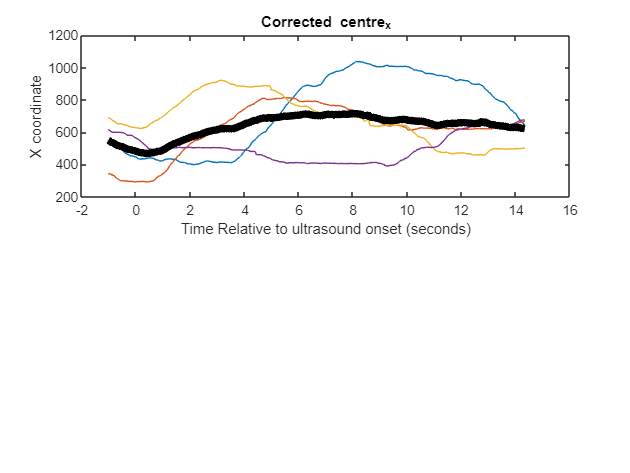

% plot centre_xcorrected
figure
subplot(2,1,1)
plot(ERF_time,centre_xcorrected)
title ('Corrected centre_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('X coordinate')
hold on
plot(ERF_time,mean(centre_xcorrected,2),'k','LineWidth',5)

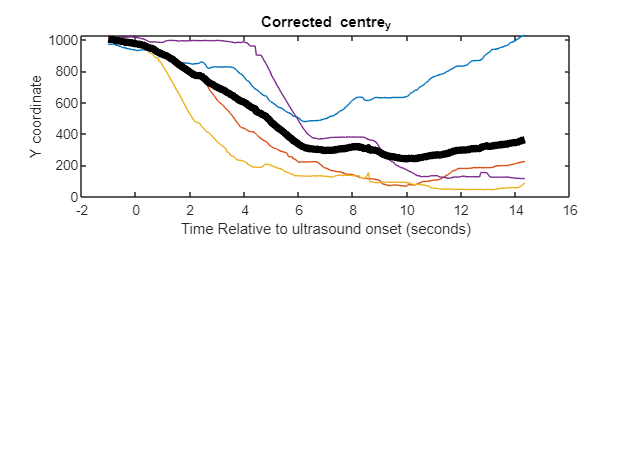


% plot centre_ycorrected
figure
subplot(2,1,1)
plot(ERF_time,centre_ycorrected)
title ('Corrected centre_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Y coordinate')
hold on
plot(ERF_time,mean(centre_ycorrected,2),'k','LineWidth',5)

Nose X and Y

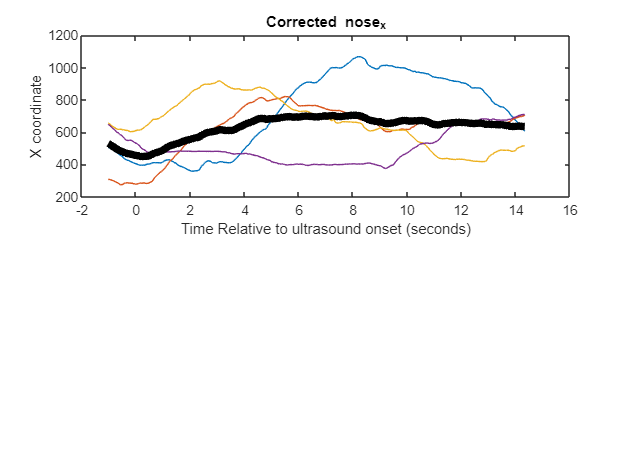

% plot nose_xcorrected
figure
subplot(2,1,1)
plot(ERF_time,nose_xcorrected)
title ('Corrected nose_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('X coordinate')
hold on
plot(ERF_time,mean(nose_xcorrected,2),'k','LineWidth',5)

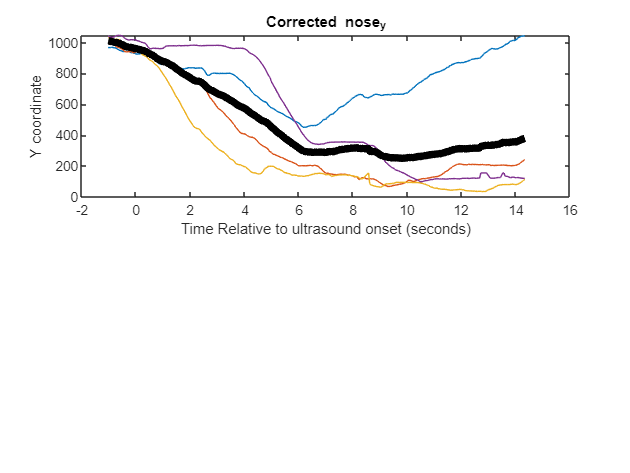


% plot nose_ycorrected
figure
subplot(2,1,1)
plot(ERF_time,nose_ycorrected)
title ('Corrected nose_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Y coordinate')
hold on
plot(ERF_time,mean(nose_ycorrected,2),'k','LineWidth',5)

Tail X and Y

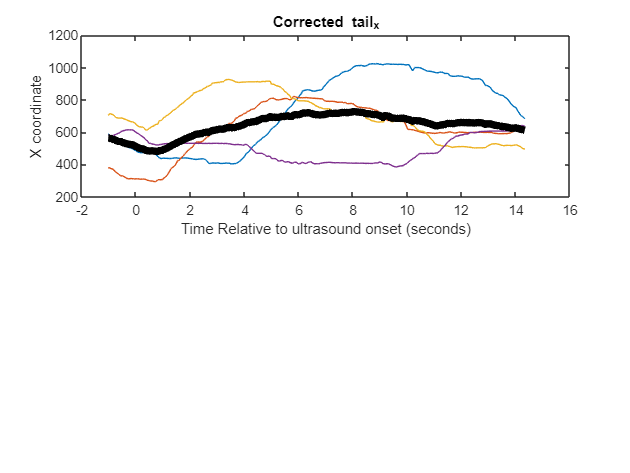

% plot tail_xcorrected
figure
subplot(2,1,1)
plot(ERF_time,tail_xcorrected)
title ('Corrected tail_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('X coordinate')
hold on
plot(ERF_time,mean(tail_xcorrected,2),'k','LineWidth',5)

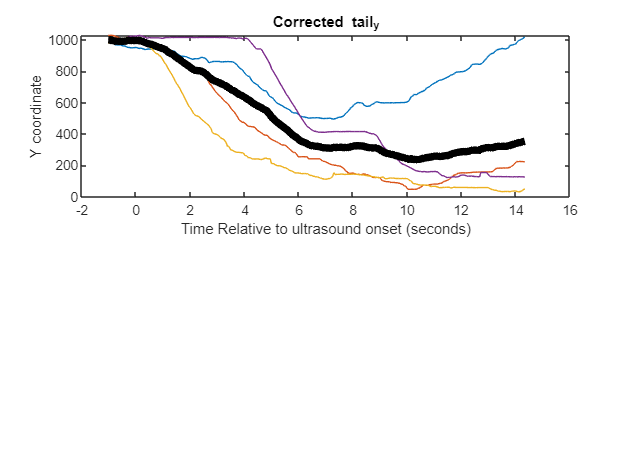


% plot tail_ycorrected
figure
subplot(2,1,1)
plot(ERF_time,tail_ycorrected)
title ('Corrected tail_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Y coordinate')
hold on
plot(ERF_time,mean(tail_ycorrected,2),'k','LineWidth',5)

The script will pause here for manual corrections.

Check the corrected centre, nose and tail plots to see if there are issues with tracking.

Manually correct errors in tracking:

- Open the respective variable (centre_xcorrected or centre_ycorrected) and update the errors manually.

- Check that errors have been resolved by clicking your cursor at the beginning of this code block and then click the "Run to End" button to restart the code from here. DO NOT click "Run" as this will restart the code from the beginning.. 

keyboard

Replace Specific centre_x and centre_y values that are problematic

Sometimes DLC tracking incorrectly labells something in the video outside of the platform as the animals body. When this happens there will be many rows that go to that specific x and y coordinates. If this happens, we can replace that point with a linear extrapolation based on the other correctly labelled points.

%centre_xcorrected(786.058 < centre_xcorrected & centre_xcorrected < 786.06)=nan;
%centre_xcorrected = fillmissing(centre_xcorrected,'linear');

%centre_ycorrected(409.24 < centre_ycorrected & centre_ycorrected < 409.26)=nan;
%centre_ycorrected = fillmissing(centre_ycorrected,'linear');

### Update trial event data

Update the centre_x and centre_y

for k = 1:length(ks)
    event_X{k}.centre_x = centre_xcorrected(:,k);
    event_X{k}.centre_y = centre_ycorrected(:,k);
    event_X{k}.nose_x = nose_xcorrected(:,k);
    event_X{k}.nose_y = nose_ycorrected(:,k);
    event_X{k}.tail_x = tail_xcorrected(:,k);
    event_X{k}.tail_y = tail_ycorrected(:,k);
end

for k = 1:length(ks)
    % calculate distance between centre and object(e.g., shelter)  -- this is A.
    event_X{k}.x_c2o = event_X{k}.shelter_x - event_X{k}.centre_x;
    event_X{k}.y_c2o = event_X{k}.shelter_y - event_X{k}.centre_y;
    event_X{k}.c2o = sqrt(event_X{k}.x_c2o.^2 + event_X{k}.y_c2o.^2);
   
    % calculate distance between nose and object(e.g., shelter)  -- this is B.
    event_X{k}.x_c2n = event_X{k}.nose_x - event_X{k}.centre_x;
    event_X{k}.y_c2n = event_X{k}.nose_y - event_X{k}.centre_y;
    event_X{k}.c2n = sqrt( event_X{k}.x_c2n.^2 + event_X{k}.y_c2n.^2 );
    
    % calculate distance between centre and object(e.g., shelter)  -- this is C.
    event_X{k}.x_n2o = event_X{k}.shelter_x - event_X{k}.nose_x;
    event_X{k}.y_n2o = event_X{k}.shelter_y - event_X{k}.nose_y;
    event_X{k}.n2o = sqrt(event_X{k}.x_n2o.^2 + event_X{k}.y_n2o.^2);
end

Calcuate the head angle with corrected position data

% calculate the angle between line a and line b when given the length of connecting line c. cos(theta) = (a^2 + b^2 - c^2)/(2*a*b)
thetaupdated = [];
Xnew = [];
for k = 1:length(ks)
c2onew(:,k) = event_X{k}.c2o;
c2nnew(:,k) = event_X{k}.c2n;
n2onew(:,k) = event_X{k}.n2o;
Xnew = (c2onew.^2 + c2nnew.^2 - n2onew.^2)./(2.*c2onew.*c2nnew);
thetaupdated(:,k) = rad2deg(acos(Xnew(:,k))); % the angle column.
event_X{k}.theta = thetaupdated(:,k);
end

Create distancecorrected variable with the updated distance form the shelter

distancecorrected = [];

for k = 1:length(ks)
    distancecorrected(:,k) = event_X{k}.c2o;
end

Calculate the speed of centre point with corrected centre_x and centre_y data

v_centrecorrected= [];

clear x y;
x = centre_xcorrected(:,:);
y = centre_ycorrected(:,:);

[lengthcentre_xcorrected,widthcentre_xcorrected]  = size(centre_xcorrected);

for i = 1:widthcentre_xcorrected;
    for ii = 2:lengthcentre_xcorrected;
        v_centrecorrected(ii,i) = pdist([x(ii-1,i) y(ii-1,i); x(ii,i) y(ii,i)], 'euclidean');
    end
end

v_centrecorrected(1,:) = v_centrecorrected(2,:);

% Update v_centre data in event_X
for k = 1:length(ks);
    event_X{k}.v_centre = v_centrecorrected(1:end,k);
end

## Set head angle, distance and speed to zero upon at the shelter

Identify the rows of the data when the animal is inside the shelter.

% event_true will be 1 when the animal is inside the shelter
correctedevent_true = [];
for k = 1:length(ks)
    correctedevent_true(:,k) = (event_X{k}.c2o < shelter_r);
    event_X{k}.event_true = correctedevent_true(:,k);
end

Identify which trials the animal arrives at the shelter.

Sumofevent_true = [];
for k = 1:length(ks)
    % the Sum of event_true will be 0 if the animal does not arrive at the
    % the Sub of event_true will be > 0 if the animal arrives at the
    % shelter
    Sumofevent_true(:,k) = sum(event_X{k}.event_true);
end

Identify the first row when the animal is inside the shelter.

% If the animal does not arrive at the shelter the last row will be selected
InshelterIndex = [];

for k = 1:length(ks)
    if sum(event_X{k}.event_true) >= 1
        InshelterIndex(:,k) = find(event_X{k}.event_true == 1,1,"first");
    elseif sum(event_X{k}.event_true) < 1
        InshelterIndex(:,k) = NaN;
    end
end

Set the distance, head angle, speed, centre_x and centre_y data to 0 after the animal arrives in the shelter

for k = 1:length(ks)
    if InshelterIndex(:,k) < length(distancecorrected);
        event_X{k}.c2o(InshelterIndex(:,k):end) = 0;
        event_X{k}.theta(InshelterIndex(:,k):end) = 0;
        event_X{k}.v_centre(InshelterIndex(:,k):end) = 0;
        event_X{k}.centre_x(InshelterIndex(:,k):end) = shelter_x;
        event_X{k}.centre_y(InshelterIndex(:,k):end) = shelter_y;
    end
end

### Plot final distance from the shelter

#### Manually correct errors in distance from shelter

distancefinal = [];
for k = 1:length(ks)
    distancefinal(:,k) = event_X{k}.c2o;
end

distancefinal = fillmissing(distancefinal, 'linear');

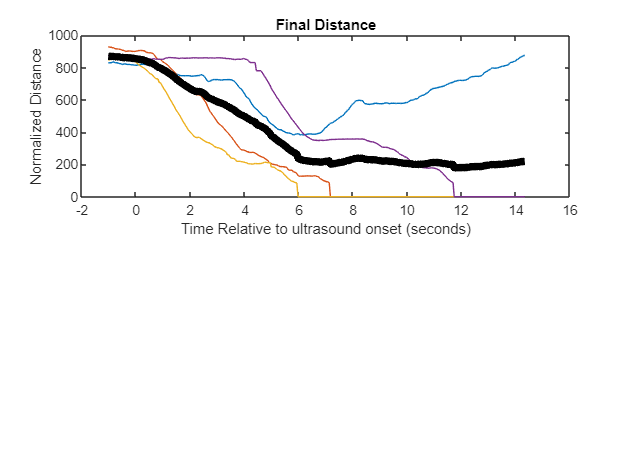

figure
subplot(2,1,1)
plot(ERF_time,distancefinal)
title ('Final Distance')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Normalized Distance')
hold on
plot(ERF_time,mean(distancefinal,2),'k','LineWidth',5)

The script will pause here for manual corrections.

Check the distance final plot to see if there are issues with tracking.

Manually correct errors in tracking:

- Open the respective variable (distancefinal) and update the errors manually.

- Check that errors have been resolved by clicking your cursor at the beginning of this code block and then click the "Run to End" button to restart the code from here. DO NOT click "Run" as this will restart the code from the beginning.. 

keyboard

### Correct speed data

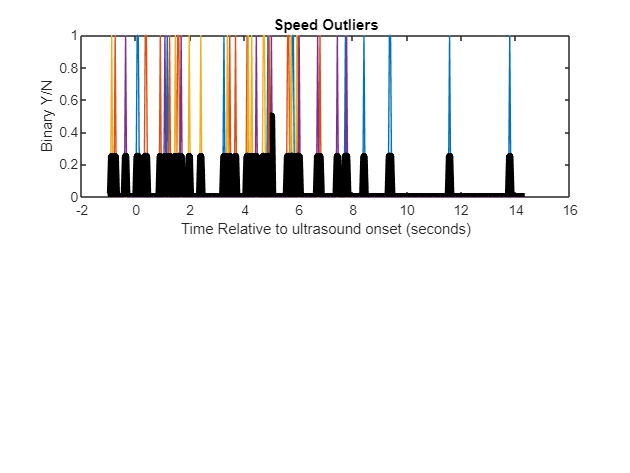

% Fill missing datapoints
for n = 1:length(event_X)
    missingspeed = fillmissing(event_X{n}.v_centre,'linear');
    event_X{n}.v_centre = missingspeed;
end

% Identify speed outliers
speedoutliers = [];

for k = 1:length(ks)
    speedoutliers(:,k) = isoutlier(event_X{k}.v_centre,"movmedian",[5 5]);
end

% Compile original speed data
originalspeed =[];
for k = 1:length(ks)
    originalspeed(:,k) = event_X{k}.v_centre;
end

% Compile corrected speed data
speedcorrected = [];

for k = 1:length(ks)
    speedcorrected(:,k) = filloutliers(event_X{k}.v_centre,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end

% Plot speed outliers
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));
figure
subplot(2,1,1)
plot(ERF_time,speedoutliers)
title ('Speed Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')
hold on
plot(ERF_time,mean(speedoutliers,2),'k','LineWidth',5)

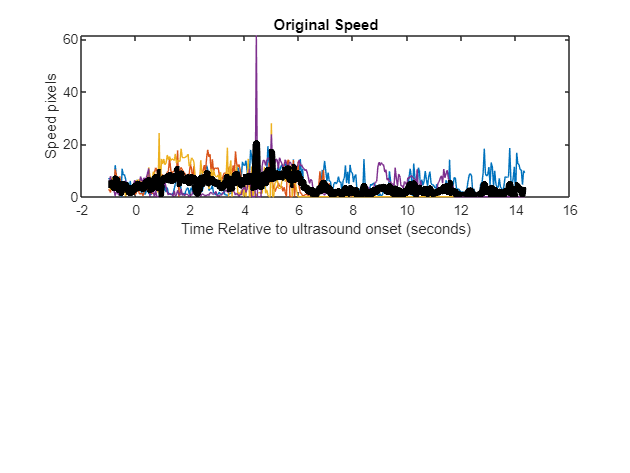


% Plot original speed
figure
subplot(2,1,1)
plot(ERF_time,originalspeed)
title ('Original Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed pixels')
hold on
plot(ERF_time,mean(originalspeed,2),'k','LineWidth',5)

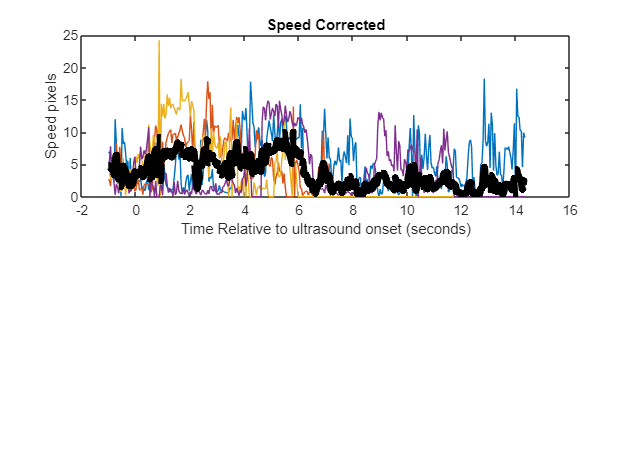


% Plot speed corrected
figure
subplot(2,1,1)
plot(ERF_time,speedcorrected)
title ('Speed Corrected')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed pixels')
hold on
plot(ERF_time,mean(speedcorrected,2),'k','LineWidth',5)

### Detect and replace abrupt changes in speedcorrected

change_threshold = 5; % Set a threshold for what is considered an abrupt change
dx_speedcorrected = diff(speedcorrected); % Calculate the difference between consecutive speedcorrected

% Find indices where the difference exceeds the threshold
abruptIndices_speedcorrected = find(abs(dx_speedcorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_speedcorrected)

           7
           9
          12
          13
          20
          46
          81
          82
          88
         117
         124
         138
         167
         168
         170
         186
         210
         216
         264
         265
         266
         267
         269
         271
         316
         326
         327
         331
         332
         334
         335
         353
         354
         359
         360
         401
         446
         450
         451
         521
         522
         523
         548
         553
         765
         766
         767
         826
         828
         833
         839
         840
         841
         865
         873
         874
         881
        1117
        1204
        1205
        1214
        1314
        1329
        1348
        1349
        1371




newspeedcorrected = [];
newspeedcorrected = speedcorrected;
newspeedcorrected(abruptIndices_speedcorrected) = NaN;

If first value in the column is NaN replace with next nonzeronumber

% Get the number of columns
numCols = size(newspeedcorrected, 2);

for col = 1:numCols
    % Find the first non-NaN value in the column
    firstNonNanIdx = find(~isnan(newspeedcorrected(:, col)), 1);
    
    if firstNonNanIdx > 1
        % If the first value is NaN, replace it with the first nonzero value
        newspeedcorrected(1, col) = newspeedcorrected(firstNonNanIdx, col);
    end
end

If last value in the column is NaN replace with previous nonzeronumber

[numRows, numCols] = size(newspeedcorrected);

for col = 1:numCols
    % Check if the last value is NaN
    if isnan(newspeedcorrected(end, col))
        % Find the last non-zero and non-NaN value in the column
        idx = find(newspeedcorrected(:, col) ~= 0 & ~isnan(newspeedcorrected(:, col)), 1, 'last');
        if ~isempty(idx)
            % Replace the NaN value with the last non-zero value
            newspeedcorrected(end, col) = newspeedcorrected(idx, col);
        end
    end
end


Set newspeedcorrected to 0 from inshelterindex

% Assuming newthetacorrected is a matrix and InshelterIndex is a vector
[rows, cols] = size(newspeedcorrected);

for col = 1:cols
    if InshelterIndex(col) <= rows
        newspeedcorrected(InshelterIndex(col):end, col) = 0;
    end
end

newspeedcorrected = fillmissing(newspeedcorrected,'linear');

Plot the updated data

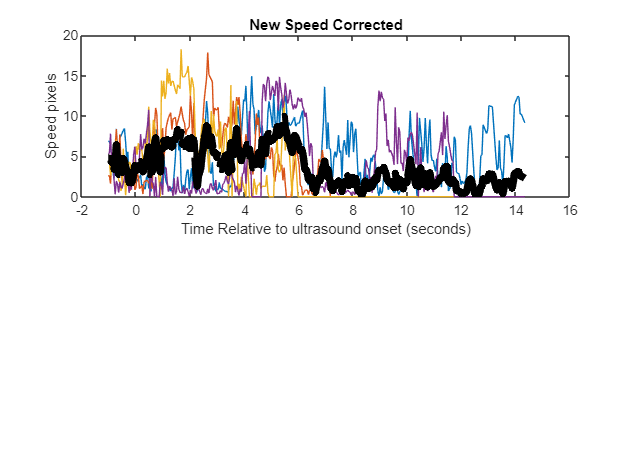

newspeedcorrected = fillmissing(newspeedcorrected, 'linear');

ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));

% Plot original speed
figure
subplot(2,1,1)
plot(ERF_time,newspeedcorrected)
title ('New Speed Corrected')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed pixels')
hold on
plot(ERF_time,mean(newspeedcorrected,2),'k','LineWidth',5)

The script will pause here for manual corrections.

Check the speedcorrected final plot to see if there are issues with tracking.

Manually correct errors in tracking:

- Open the respective variable (speedcorrected) and update the errors manually.

- Check that errors have been resolved by clicking your cursor at the beginning of this code block and then click the "Run to End" button to restart the code from here. DO NOT click "Run" as this will restart the code from the beginning.

keyboard

Save speed data converted in meters/sec

speedmeterspersec =[];
for k = 1:length(event_X)
    speedmeterspersec(:,k) = (newspeedcorrected(:,k)/0.042)/(pixelsperm);
end

% 0.042 represents the number of seconds per row of data. Since there were
% 24 rows per second each datapoint represents 1/24 or 0.042

% Update speedcorrected
speedcorrected = newspeedcorrected;

#### **Correct errors in head angle**

If there are issues with head angle, manually correct them by opening "thetacorrected" variable. Fill in the problematic points with the nearest good value. 

Re run this code block to check your distance plots after manually correcting data

thetacorrected = [];

for k = 1:length(ks)
    thetacorrected(:,k) = event_X{k}.theta;
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
    thetacorrected = fillmissing(thetacorrected, 'linear');
end
close all

### Detect and replace abrupt changes in thetacorrected

change_threshold = 15; % Set a threshold for what is considered an abrupt change
dx_thetacorrected = diff(thetacorrected); % Calculate the difference between consecutive thetacorrected

% Find indices where the difference exceeds the threshold
abruptIndices_thetacorrected = find(abs(dx_thetacorrected) > change_threshold) + 1;

% Display the abrupt indices
disp('Abrupt changes detected at indices:');

Abrupt changes detected at indices:


disp(abruptIndices_thetacorrected);

          82
         168
         190
         225
         236
         244
         400
         519
         521
         553
         862
        1087
        1088
        1095
        1209
        1210
        1380




newthetacorrected = [];
newthetacorrected = thetacorrected;
newthetacorrected(abruptIndices_thetacorrected) = NaN;
newthetacorrected(newthetacorrected < 1) = NaN;

for col = 1:size(newthetacorrected, 2)
    % Check if the last value in the column is zero
    if newthetacorrected(end, col) == NaN
        % Find the previous non-zero value in the column
        nonZeroIdx = find(newthetacorrected(:, col) ~= 0, 1, 'last');
        
        if ~isempty(nonZeroIdx)
            % Replace the last value with the previous non-zero value
            newthetacorrected(end, col) = newthetacorrected(nonZeroIdx, col);
        end
    end
end

newthetacorrected = fillmissing(newthetacorrected,'linear');

% Set newthetacorrected to 0 from inshelterindex
% Assuming newthetacorrected is a matrix and InshelterIndex is a vector
[rows, cols] = size(newthetacorrected);

for col = 1:cols
    if InshelterIndex(col) <= rows
        newthetacorrected(InshelterIndex(col):end, col) = 0;
    end
end

% Update thetacorrected
thetacorrected = newthetacorrected;

% Moving average window size
windowSize = 25;

[rows, cols] = size(thetacorrected);

for col = 1:size(thetacorrected, 2)
    % Calculate the moving average
    movingAvg = movmean(thetacorrected(:, col), windowSize);
    
    % Identify outliers (data points deviating significantly from the trend)
    deviations = abs(thetacorrected(:, col) - movingAvg);
    threshold = 2 * std(deviations);  % You can adjust this threshold
    
    % Replace outliers with NaN (or mark them for interpolation)
    outliers = deviations > threshold;
    thetacorrected(outliers, col) = NaN;
end

If first value in the column is NaN replace with next nonzeronumber

% % Get the number of columns
% numCols = size(thetacorrected, 2);
% 
% for col = 1:numCols
%     % Find the first non-NaN value in the column
%     firstNonNanIdx = find(~isnan(thetacorrected(:, col)), 1);
%     
%     if firstNonNanIdx > 1
%         % If the first value is NaN, replace it with the first nonzero value
%         thetacorrected(1, col) = thetacorrected(firstNonNanIdx, col);
%     end
% end

If last value in the column is NaN replace with previous nonzeronumber

% [numRows, numCols] = size(thetacorrected);
% 
% for col = 1:numCols
%     % Check if the last value is NaN
%     if isnan(thetacorrected(end, col))
%         % Find the last non-zero and non-NaN value in the column
%         idx = find(thetacorrected(:, col) ~= 0 & ~isnan(thetacorrected(:, col)), 1, 'last');
%         if ~isempty(idx)
%             % Replace the NaN value with the last non-zero value
%             thetacorrected(end, col) = thetacorrected(idx, col);
%         end
%     end
% end

thetacorrected = fillmissing(thetacorrected,'linear');

% Set newthetacorrected to 0 from inshelterindex
% Assuming newthetacorrected is a matrix and InshelterIndex is a vector
[rows, cols] = size(thetacorrected);

for col = 1:cols
    if InshelterIndex(col) <= rows
        thetacorrected(InshelterIndex(col):end, col) = 0;
    end
end

Plot the updated data

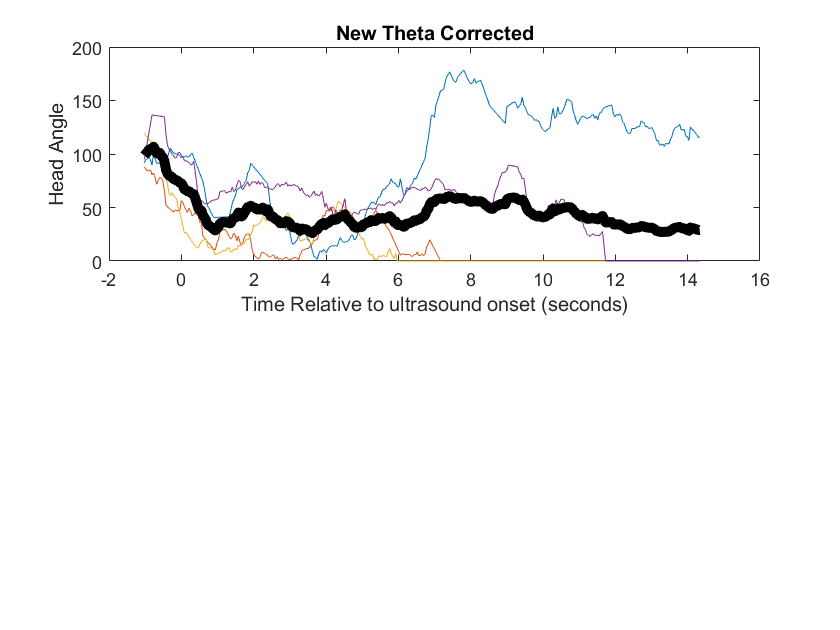

thetacorrected = fillmissing(thetacorrected,'linear');

ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));

% Plot original speed
figure
subplot(2,1,1)
plot(ERF_time,thetacorrected)
title ('New Theta Corrected')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Head Angle')
hold on
plot(ERF_time,mean(thetacorrected,2),'k','LineWidth',5)

The script will pause here for manual corrections.

Check the thetacorrected final plot to see if there are issues with tracking.

Manually correct errors in tracking:

- Open the respective variable (thetacorrected) and update the errors manually.

- Check that errors have been resolved by clicking your cursor at the beginning of this code block and then click the "Run to End" button to restart the code from here. DO NOT click "Run" as this will restart the code from the beginning.

keyboard

### Check if outliers have been resolved by plotting all the timeseries data for each escape

Each escape is represented by a column. The distance, speed and head angle plots for each escape should be visualized as stacked line graphs.

Look at the line graphs and identify any remaining outliers by eye.

- No remaining outliers? Click the "Run to end" button and overwrite your MATLAB file to ensure you have the most up to date data. 

- If there are remaining outliers? You must manually correct the data.

How to manually correct the data:

- Open the variable from the workspace that you need to correct. The variables will be either distancefinal, speedcorrected or thetacorrected.

- Focus on the column corresponding to the escape with the tracking issue. For example Column 1 = Escape 1 = top graph in the stacked plots.

- Find the problematic cell and replace with the nearest value that is not problematic by copy and pasting.

- Click the left blue bar on this code block to see whether the issue was resolved.

- Repeat as necessary.

- If all points are resolved click "Run to End" button and overwrite your MATLAB file to ensure you have the most up to date data. 

% stackedplot(distancefinal)
% stackedplot(speedcorrected)
% stackedplot(thetacorrected)
% 
% keyboard

#### **Update event trial data with corrected speed and head angle data**

%Replace the speed data in the event_X variable with the speed corrected data
for k = 1:length(ks)
    event_X{k}.v_centre = speedmeterspersec(:,k);
end

%Replace the theta data in the event_X variable with the theta corrected data
for k = 1:length(ks)
    event_X{k}.theta = newthetacorrected(:,k);
end

## Plot datapoints around ultrasound cue onsets 

Timeseries data and rasterplots

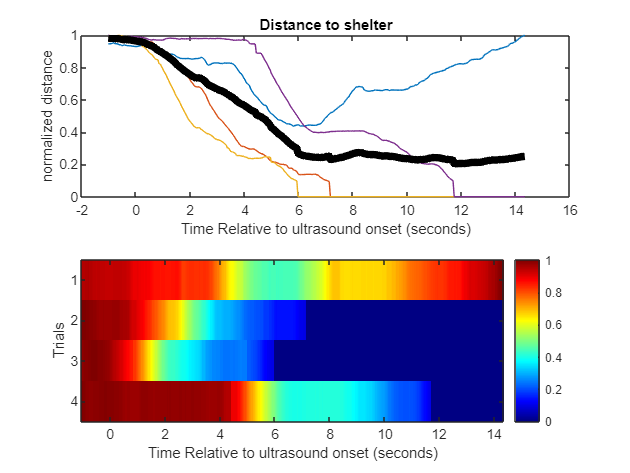

% Create new variables
speed = [];theta = [];tail_x = [];tail_y = [];nose_x = [];nose_y = [];centre_x =[];centre_y =[]; maxDistance = []; distance = []; ndistance = [];

for k = 1:length(ks)
    speed(:,k) = speedcorrected(:,k); theta(:,k) = thetacorrected(:,k); distance(:,k) = distancefinal(:,k); maxDistance(:,k) = max(event_X{k}.c2o); ndistance(:,k) = distancefinal(:,k)/maxDistance(:,k);
    tail_x(:,k) = event_X{k}.tail_x;tail_y(:,k) = event_X{k}.tail_y; nose_x(:,k) = event_X{k}.nose_x;nose_y(:,k) = event_X{k}.nose_y;
    centre_x(:,k) = event_X{k}.centre_x;centre_y(:,k) = event_X{k}.centre_y;
end

close all

ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));

% Plot final normalized distance from shelter
figure
subplot(2,1,1)
plot(ERF_time,ndistance)
title ('Distance to shelter')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('normalized distance')
hold on
plot(ERF_time,mean(ndistance,2),'k','LineWidth',5)

subplot(2,1,2)
imagesc(ERF_time,1:length(ks),ndistance')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Trials')
colormap jet
colorbar

% Plot final speed 
figure
subplot(2,1,1)
plot(ERF_time,speedmeterspersec)
title ('speed around ultrasound onset')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('speed')
hold on
plot(ERF_time,mean(speedmeterspersec,2),'k','LineWidth',5)


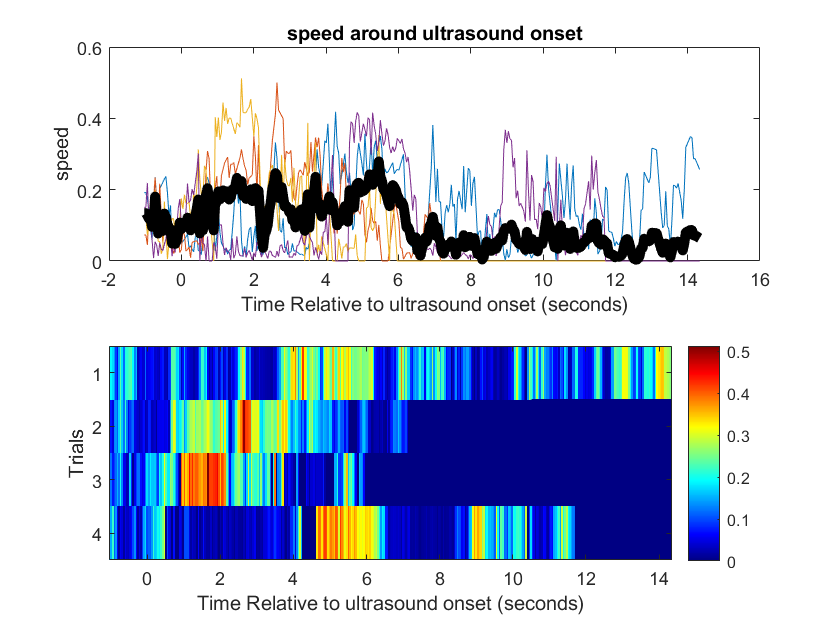

subplot(2,1,2)
imagesc(ERF_time,1:length(ks),speedmeterspersec')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Trials')
colormap jet
colorbar
figure
subplot(2,1,1)

% Plot head angle 
plot(ERF_time,thetacorrected)
title ('theta around ultrasound onset')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('theta')
hold on
plot(ERF_time,mean(thetacorrected,2),'k','LineWidth',5)


subplot(2,1,2)
imagesc(ERF_time,1:length(ks),thetacorrected')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Trials')
colormap jet
colorbar

## Condense timeseries data into 1sec bins

### Normalized Distance Binned Data (10 bins)

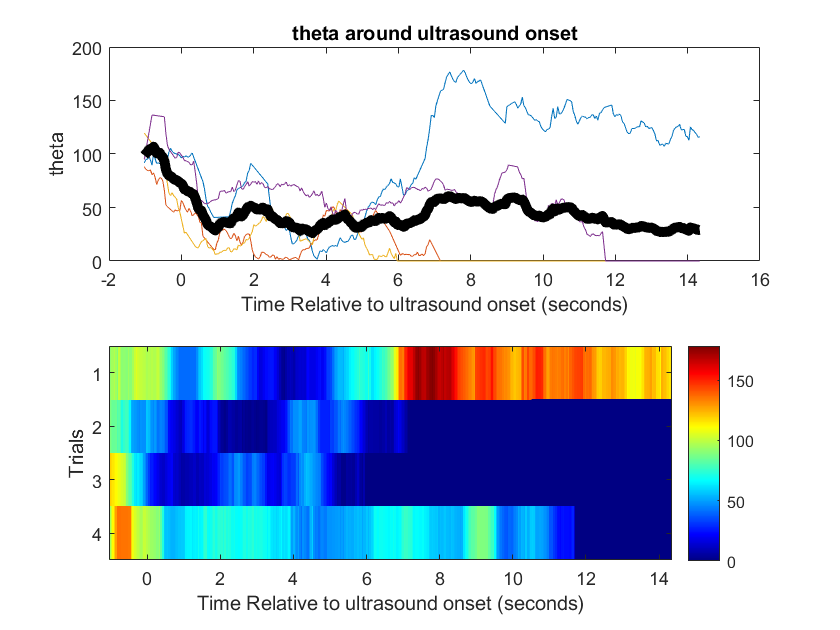

% binnedndistance = []
% for k = 1:length(ks)
%     %Bin 1 sec before ultrasound
%     binnedndistance(1:1,k) = mean(ndistance(1:24,k));
%     % Bin 1 sec after ultrasound
%     binnedndistance(2:2,k) = mean(ndistance(25:48,k));
%     % Bin 2 sec after ultrasound
%     binnedndistance(3:3,k) = mean(ndistance(49:72,k));
%     % Bin 3 sec after ultrasound
%     binnedndistance(4:4,k) = mean(ndistance(73:96,k));
%     % Bin 4 sec after ultrasound

%     binnedndistance(5:5,k) = mean(ndistance(97:120,k));
%     % Bin 5 sec after ultrasound
%     binnedndistance(6:6,k) = mean(ndistance(121:144,k));
%     % Bin 6 sec after ultrasound
%     binnedndistance(7:7,k) = mean(ndistance(145:168,k));
%     % Bin 7 sec after ultrasound
%     binnedndistance(8:8,k) = mean(ndistance(169:192,k));
%     % Bin 8 sec after ultrasound
%     binnedndistance(9:9,k) = mean(ndistance(193:216,k));
%     % Bin 9 sec after ultrasound
%     binnedndistance(10:10,k) = mean(ndistance(217:240,k));
% end
% 
% Binned_Time = [1:10]

### Speed Binned Data (10 bins)

% binnedspeed = []
% 
% for k = 1:length(ks)
%     %Bin 1 sec before ultrasound
%     binnedspeed(1:1,k) = mean(speed(1:24,k));
%     % Bin 1 sec after ultrasound
%     binnedspeed(2:2,k) = mean(speed(25:48,k));
%     % Bin 2 sec after ultrasound
%     binnedspeed(3:3,k) = mean(speed(49:72,k));
%     % Bin 3 sec after ultrasound
%     binnedspeed(4:4,k) = mean(speed(73:96,k));
%     % Bin 4 sec after ultrasound
%     binnedspeed(5:5,k) = mean(speed(97:120,k));
%     % Bin 5 sec after ultrasound
%     binnedspeed(6:6,k) = mean(speed(121:144,k));
%     % Bin 6 sec after ultrasound
%     binnedspeed(7:7,k) = mean(speed(145:168,k));
%     % Bin 7 sec after ultrasound
%     binnedspeed(8:8,k) = mean(speed(169:192,k));
%     % Bin 8 sec after ultrasound
%     binnedspeed(9:9,k) = mean(speed(193:216,k));
%     % Bin 9 sec after ultrasound
%     binnedspeed(10:10,k) = mean(speed(217:240,k));
% end
% 
% Binned_Time = [1:10]

### Theta Binned Data (10 bins)

% binnedtheta = []
% for k = 1:length(ks)
%     %Bin 1 sec before ultrasound
%     binnedtheta(1:1,k) = mean(theta(1:24,k));
%     % Bin 1 sec after ultrasound
%     binnedtheta(2:2,k) = mean(theta(25:48,k));
%     % Bin 2 sec after ultrasound
%     binnedtheta(3:3,k) = mean(theta(49:72,k));
%     % Bin 3 sec after ultrasound
%     binnedtheta(4:4,k) = mean(theta(73:96,k));
%     % Bin 4 sec after ultrasound
%     binnedtheta(5:5,k) = mean(theta(97:120,k));
%     % Bin 5 sec after ultrasound
%     binnedtheta(6:6,k) = mean(theta(121:144,k));
%     % Bin 6 sec after ultrasound
%     binnedtheta(7:7,k) = mean(theta(145:168,k));
%     % Bin 7 sec after ultrasound
%     binnedtheta(8:8,k) = mean(theta(169:192,k));
%     % Bin 8 sec after ultrasound
%     binnedtheta(9:9,k) = mean(theta(193:216,k));
%     % Bin 9 sec after ultrasound
%     binnedtheta(10:10,k) = mean(theta(217:240,k));
% end
% 
% Binned_Time = [1:10]

### Plot the binned data

% % Plot binned normalized distance
% figure
% subplot(2,1,1)
% plot(Binned_Time,binnedndistance)
% title ('Distance to shelter')
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('normalized distance')
% hold on
% plot(Binned_Time,mean(binnedndistance,2),'k','LineWidth',5)
% 
% subplot(2,1,2)
% imagesc(Binned_Time,1:length(ks),binnedndistance')
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('Trials')
% colormap jet
% colorbar
% 
% % Plot binned speed data
% figure
% subplot(2,1,1)
% plot(Binned_Time,binnedspeed)
% title ('Speed of escape')
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('Speed (m/s)')
% hold on
% plot(Binned_Time,mean(binnedspeed,2),'k','LineWidth',5)
% 
% subplot(2,1,2)
% imagesc(Binned_Time,1:length(ks),binnedspeed')
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('Trials')
% colormap jet
% colorbar
% 
% % Plot binned theta data
% figure
% subplot(2,1,1)
% plot(Binned_Time,binnedtheta)
% title ('Theta relative to shelter')
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('normalized theta')
% hold on
% plot(Binned_Time,mean(binnedtheta,2),'k','LineWidth',5)
% 
% subplot(2,1,2)
% imagesc(Binned_Time,1:length(ks),binnedtheta')
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('Trials')
% colormap jet
% colorbar

#### Compile the timeseries data into one variable and export to csv

Not absolutly necessary to export the data if we are saving the MATLAB file

% TimeseriesData.ndistance = ndistance
% TimeseriesData.speed = speed
% TimeseriesData.theta = theta
% 
% TimeseriesData
% 
% % Export timeseries data as csv
% % writetable(struct2table(TimeseriesData), 'TimeseriesData.csv')
% 
% BinnedTimeseriesData.binnedtheta = binnedtheta
% BinnedTimeseriesData.binnedspeed = binnedspeed
% BinnedTimeseriesData.binnedndistance = binnedndistance
% 
% BinnedTimeseriesData
% 
% % Export binned timeseries data in csv
% % writetable(struct2table(BinnedTimeseriesData), 'BinnedTimeseriesData.csv')

## Analyze Escape Data

% Create new escape data variables
departure_time = [];arrival_time = [];escape_duration = [];arrivalIndex = [];max_time = [];max_speed = [];max_elapsed = [];
escape_distance = []; escape_linearity = []; escape_linearity2 = []; linear_distance = []; linear_distancemeters = []; escape_accuracy = [];
x_linear = []; y_linear = []; escape_distancetravelled =[]; escape_distancemeters = [];

ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));

% Find the row number at the end of the 9s trial, start of trial 0s, and
% end of 15s window
[~, col] = min(abs(ERF_time - 9), [], 2);
[~, start] = min(abs(ERF_time - 0), [], 2);
[~, finish] = min(abs(ERF_time - 14), [], 2);
% Display the column number
disp(['Column closest to 9s: ', num2str(col)]);
disp(['Column closest to 0s: ', num2str(start)]);
disp(['Column closest to 14s: ', num2str(finish)]);

% Create new variables that correspond to data for the 9s ultrasound
% removing the 1s before ultrasound
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));
ERF_time9s = ERF_time(1, start:col);
thetacorrected9s = thetacorrected(start:col,:);
ERF_timetranspose = ERF_time';
speedmeterspersec9s = speedmeterspersec(start:col,:);

% Create new variables that correspond to data for the 14s after the ultrasound
% removing the 1s before ultrasound
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));
ERF_time14s = ERF_time(1, start:finish);
thetacorrected14s = thetacorrected(start:finish,:);
ERF_timetranspose = ERF_time';
speedmeterspersec14s = speedmeterspersec(start:finish,:);

#### Duration

We are selecting the row of the timestamp data that corresponds to the first row when the animal is inside the shelter (InshelterIndex).

for k = 1:length(ks);

Column closest to 9s: 236


    event_X{k}.Time = ERF_timetranspose;

Column closest to 0s: 25


end

Column closest to 14s: 353


% Assume `distance` is a matrix where each column represents a trial
[numRows, numCols] = size(distance);
firstZeroRow = NaN(1, numCols); % Preallocate an array to store the row indices

% Loop through each column to find the first occurrence of zero in each column
for i = 1:numCols
    % Find the index of the first row where the distance is zero
    idx = find(distance(:, i) == 0, 1);
    
    % Store the row index in firstZeroRow if a zero is found, otherwise leave NaN
    if ~isempty(idx)
        firstZeroRow(i) = idx;
    end
end

Duration (9s)

arrival_time9s =[];
%Identify time from the ultrasound onset when the animal arrived at theshelter
for n = 1:length(firstZeroRow)
    % Check if firstZeroRow(n) is NaN or greater than col
    if isnan(firstZeroRow(n)) || firstZeroRow(n) > col
        arrival_time9s(n) = 9;
    else 
    arrival_time9s(n) = (ERF_time(firstZeroRow(n))); % find the time of arrival
    end
end

% Display the accuracy
disp(['Arrival Time 9s: ', num2str(arrival_time9s)]);

Duration (14s)

arrival_time14s = [];
%Identify time from the ultrasound onset when the animal arrived at theshelter
for n = 1:length(firstZeroRow)
    % Check if firstZeroRow(n) is NaN or greater than col
    if isnan(firstZeroRow(n)) || firstZeroRow(n) > finish
        arrival_time14s(n) = 14;
    else 
    arrival_time14s(n) = (ERF_time(firstZeroRow(n))); % find the time of arrival
    end
end

% Display the accuracy
disp(['Arrival Time 14s: ', num2str(arrival_time14s)]);

Arrival Time 9s: 9      7.1665      5.9721           9


#### Accuracy

For animals that do not arrive at the shelter we are computing a 10% decrease in accuracy when the animal is the diameter of the shelter away from the shelter zone.

For animals that arrive at the shelter before the end of the 9s the accuracy is set to 100%.

Accuracy (9s)

escape_accuracy9s = [];
for n = 1:length(event_X)
if  isnan(firstZeroRow(n)) || firstZeroRow(n) > col;
     escape_accuracy9s(n) = 100 - 10 * round((event_X{n}.c2o(col)./(2*shelter_r)));
else firstZeroRow(n) < col;
        escape_accuracy9s(n) = 100; 
    end
    if escape_accuracy9s(n) < 0
        escape_accuracy9s(n) = 0
    end
end

% Display the accuracy

Arrival Time 14s: 14      7.16648      5.97207      11.7308


disp(['Accuracy 9s: ', num2str(escape_accuracy9s)]);

Accuracy (14s)

escape_accuracy14s = [];
for n = 1:length(event_X)
if  isnan(firstZeroRow(n)) || firstZeroRow(n) > finish;
     escape_accuracy14s(n) = 100 - 10 * round((event_X{n}.c2o(col)./(2*shelter_r)));
else firstZeroRow(n) < finish;
        escape_accuracy14s(n) = 100; 
    end
    if escape_accuracy14s(n) < 0
        escape_accuracy14s(n) = 0
    end
end

% Display the accuracy
disp(['Accuracy 14s: ', num2str(escape_accuracy14s)]);

Accuracy 9s: 70  100  100   80


#### Linear Distance

Linear Distance (9s)

linear_distance9s = [];
% Create new variables for centre_x and centre_y corresponding to the 9s ultrasound removing the 1s
% before the ultrasound 
centre_xcorrected9sec = centre_xcorrected(bl:col,:);
centre_ycorrected9sec = centre_ycorrected(bl:col,:);

% Extract the first coordinates
start_x = centre_xcorrected9sec(1,:);
start_y = centre_ycorrected9sec(1,:);

% Initialize the matrix with zeros (or NaNs) for other rows if desired

shelter_x_replicated9s = zeros(1, length(ks)); % you can also use NaN(size) if you prefer NaNs
% Insert the value of shelter_x in the first row across numColumns columns

Accuracy 14s: 70  100  100  100


shelter_x_replicated9s(1, :) = shelter_x;

shelter_y_replicated9s = zeros(1, length(ks)); % you can also use NaN(size) if you prefer NaNs
% Insert the value of shelter_x in the first row across numColumns columns
shelter_y_replicated9s(1, :) = shelter_y;

% Compute the Euclidean distance between the starting point and the shelter point
for k = 1:length(ks)
linear_distance9s(:,k) = sqrt((shelter_x_replicated9s(:,k) - start_x(:,k)).^2 + (shelter_y_replicated9s(:,k) - start_y(:,k)).^2);
end

% Display the linear distance
disp(['Linear distance to shelter 9s: ', num2str(linear_distance9s)]);

Linear Distance (14s)

linear_distance14s = [];
% Create new variables for centre_x and centre_y corresponding to the 14s after the ultrasound removing the 1s
% before the ultrasound 
centre_xcorrected14s = centre_xcorrected(bl:finish,:);
centre_ycorrected14s = centre_ycorrected(bl:finish,:);

% Extract the first coordinates
start_x = centre_xcorrected9sec(1,:);
start_y = centre_ycorrected9sec(1,:);

% Initialize the matrix with zeros (or NaNs) for other rows if desired

shelter_x_replicated14s = zeros(1, length(ks)); % you can also use NaN(size) if you prefer NaNs
% Insert the value of shelter_x in the first row across numColumns columns
shelter_x_replicated14s(1, :) = shelter_x;

Linear distance to shelter 9s: 814.737      900.2567      837.8289      869.0531



shelter_y_replicated14s = zeros(1, length(ks)); % you can also use NaN(size) if you prefer NaNs
% Insert the value of shelter_x in the first row across numColumns columns
shelter_y_replicated14s(1, :) = shelter_y;

% Compute the Euclidean distance between the starting point and the shelter point
for k = 1:length(ks)
linear_distance14s(:,k) = sqrt((shelter_x_replicated14s(:,k) - start_x(:,k)).^2 + (shelter_y_replicated14s(:,k) - start_y(:,k)).^2);
end

% Display the linear distance
disp(['Linear distance to shelter 14s: ', num2str(linear_distance14s)]);

#### Distance Travelled

Distance travelled (9s)

total_distance9s = [];
% Calculate the differences between consecutive points
dx9s = diff(centre_xcorrected9sec);
dy9s = diff(centre_ycorrected9sec);

% Compute the distance for each segment
distances9s = sqrt(dx9s.^2 + dy9s.^2);

n = length(distances9s);

for i = 2:(n-1) % Loop through each element, ignoring the first and last
    if distances9s(i) == 0 && distances9s(i-1) ~= 0 && distances9s(i+1) ~= 0
        distances9s(i) = NaN; % Replace isolated zero with NaN
    end
end

Linear distance to shelter 14s: 814.737      900.2567      837.8289      869.0531



distances9s = fillmissing(distances9s, 'linear')
% distances9s = filloutliers(distances9s, 'linear', 'movmedian', [5 5], 'ThresholdFactor', 5);

%set distances9s to zero from first arrival at the shelter
for n = 1:length(ks)
    for k = 1:size(distances9s, 2)
        % Only proceed if firstZeroRow(k) is a valid, finite index
        if ~isnan(firstZeroRow(k)) && isfinite(firstZeroRow(k)) && firstZeroRow(k) <= size(distances9s, 1)
            distances9s(firstZeroRow(k):end, k) = 0;
        end
    end
end

% Sum up all distances to get the total distance traveled
total_distance9s = sum(distances9s);

% Display the total distance
disp(['Total distance traveled 9s: ', num2str(total_distance9s)]);


distances9s =     1.7243    1.1460    6.2678    3.6285
    6.4601    2.8137    5.2132    4.0099
    5.5731    2.6485    6.6328    3.8165
    2.4234    0.9866    5.7966    4.9429
    2.6912    1.1464    5.7676    7.7490
    1.2888    1.4022    5.9113    5.8474
    1.5339    0.3242    4.3134    6.1139
    1.1557    1.8814    3.2919    7.1965
    0.9228    4.3442    6.9947    6.6049
    2.3508    6.9541    5.7983    7.3631


% Total distance travelled meters
escape_distancemeters9s = total_distance9s/pixelsperm;

Distance Travelled (14s)

total_distance14s = [];
% Calculate the differences between consecutive points
dx14s = diff(centre_xcorrected14s);
dy14s = diff(centre_ycorrected14s);

% Compute the distance for each segment
distances14s = sqrt(dx14s.^2 + dy14s.^2);

n = length(distances14s);

for i = 2:(n-1) % Loop through each element, ignoring the first and last
    if distances14s(i) == 0 && distances14s(i-1) ~= 0 && distances14s(i+1) ~= 0
        distances14s(i) = NaN; % Replace isolated zero with NaN
    end

Total distance traveled 9s: 1167.3915      1155.8926      1122.7575      919.84904


end

distances14s = fillmissing(distances14s, 'linear')
% distances14s = filloutliers(distances14s,'linear', "movmedian" ,[5 5]);

%set distances14s to zero from first arrival at the shelter
for n = 1:length(ks)
    for k = 1:size(distances14s, 2)
        % Only proceed if firstZeroRow(k) is a valid, finite index
        if ~isnan(firstZeroRow(k)) && isfinite(firstZeroRow(k)) && firstZeroRow(k) <= size(distances9s, 1)
            distances14s(firstZeroRow(k):end, k) = 0;
        end
    end
end

% Sum up all distances to get the total distance traveled
total_distance14s = sum(distances14s);

% Display the total distance
disp(['Total distance traveled 14s: ', num2str(total_distance14s)]);


distances14s =     1.7243    1.1460    6.2678    3.6285
    6.4601    2.8137    5.2132    4.0099
    5.5731    2.6485    6.6328    3.8165
    2.4234    0.9866    5.7966    4.9429
    2.6912    1.1464    5.7676    7.7490
    1.2888    1.4022    5.9113    5.8474
    1.5339    0.3242    4.3134    6.1139
    1.1557    1.8814    3.2919    7.1965
    0.9228    4.3442    6.9947    6.6049
    2.3508    6.9541    5.7983    7.3631


% Total distance travelled meters
escape_distancemeters14s = total_distance14s/pixelsperm;

**Linearity**

Compute the ratio of linear distance between position at ultrasound onset to the distance travelled during escape

We computed the linearity only for trials that were successful. This is because in trials where animals were unsuccessful the distance travelled in the 9s may be less than their distance from the shelter at ultrasound onset.

Linearity (9s)

escape_linearity9s = [];
for n = 1:length(event_X);
    if escape_accuracy9s(n) < 100;
        escape_linearity9s(n) = NaN;
    else
        escape_linearity9s(n) = linear_distance9s(n)/total_distance9s(n);
    end
end

% Display the total distance
disp(['Linearity 9s: ', num2str(escape_linearity9s)]);

Linearity (14s)

escape_linearity14s = [];

Total distance traveled 14s: 1729.0441      1155.8926      1122.7575      1440.8797


for n = 1:length(event_X);
    if escape_accuracy14s(n) < 100;
        escape_linearity14s(n) = NaN;
    else
        escape_linearity14s(n) = linear_distance14s(n)/total_distance14s(n);
    end
end

% Display the total distance
disp(['Linearity 14s: ', num2str(escape_linearity14s)]);

**Maximum Speed, Time at Maximum Speed, Head Angle at Maximum Speed**

Compute the maximum speed during teach trial, identify the time of maximum speed, identify the head angle at the maximum speed

Maximum Speed, Time at Maximum Speed, Head Angle at Maximum Speed (9s)

% find row index and value at the max speed during the 9s.
% M_data represents speed data and I_data represents row number.
[M_data9s,I_data9s] = max(speedmeterspersec9s);

Linearity 9s: NaN     0.7788412     0.7462243           NaN


max_speed9s = M_data9s; % find the max speed in meters/sec
max_elapsed9s = (ERF_time9s(I_data9s)); % find the time after ultrasound onset when speed is max.
finalvaluematrix9s = thetacorrected9s(I_data9s,1:width(centre_xcorrected)); %
max_theta9s = transpose(diag(finalvaluematrix9s)); %find the theta a maximum speed

% Display the total distance
disp(['Max Speed: ', num2str(max_speed9s)]);
disp(['Time at Max Speed: ', num2str(max_elapsed9s)]);
disp(['Head Angle at Max Speed: ', num2str(max_theta9s)]);

Maximum Speed, Time at Maximum Speed, Head Angle at Maximum Speed (14s)

% find row index and value at the max speed during the 9s.
% M_data represents speed data and I_data represents row number.
[M_data14s,I_data14s] = max(speedmeterspersec14s);

Linearity 14s: NaN     0.7788412     0.7462243     0.6031407


max_speed14s = M_data14s; % find the max speed in meters/sec
max_elapsed14s = (ERF_time14s(I_data14s)); % find the time after ultrasound onset when speed is max.
finalvaluematrix14s = thetacorrected14s(I_data14s,1:width(centre_xcorrected)); %
max_theta14s = transpose(diag(finalvaluematrix14s)); %find the theta a maximum speed

% Display the total distance
disp(['Max Speed: ', num2str(max_speed14s)]);
disp(['Time at Max Speed: ', num2str(max_elapsed14s)]);
disp(['Head Angle at Max Speed: ', num2str(max_theta14s)]);

#### Compile the escape data into one variable and export to csv

Not absolutly necessary to export the data if we are saving the MATLAB file

clear escape

% Save the escape data in a table
escapedata9s = [];
escapedata9s(1,:) = escape_accuracy9s;

Max Speed: 0.4184      0.5006     0.51191     0.41667


escapedata9s(2,:) = round(arrival_time9s,3);

Time at Max Speed: 4.2658      2.6448      1.6636       4.863


escapedata9s(3,:) = round(total_distance9s,3);

Head Angle at Max Speed: 14.5757      4.07837      14.5973      43.9011


escapedata9s(4,:) = round(escape_linearity9s,3);
escapedata9s(5,:) = round(max_speed9s,4);
escapedata9s(6,:) = round(max_elapsed9s,3);
escapedata9s(7,:) = round(max_theta9s,3);
escapedata9s(8,:) = round(escape_distancemeters9s,3);
escapedata9s

escapedata14s = [];
escapedata14s(1,:) = escape_accuracy14s;
escapedata14s(2,:) = round(arrival_time14s,3);
escapedata14s(3,:) = round(total_distance14s,3);

Max Speed: 0.4184      0.5006     0.51191     0.41667


escapedata14s(4,:) = round(escape_linearity14s,3);

Time at Max Speed: 4.2658      2.6448      1.6636       4.863


escapedata14s(5,:) = round(max_speed14s,4);

Head Angle at Max Speed: 14.5757      4.07837      14.5973      43.9011


escapedata14s(6,:) = round(max_elapsed14s,3);
escapedata14s(7,:) = round(max_theta14s,3);
escapedata9s(8,:) = round(escape_distancemeters14s,3);
escapedata14s

% export escape data in csv file
% writetable(struct2table(escapedata), 'Escape.csv')

## Visualize event trajectories with speed or theta signals from cueonset to cueoffset

This block of code will create a visual depiction of the platform, the shelter and the trajectory the animal took during their escape from an arial view.

9s

close all
numTrials = width(centre_xcorrected9sec);  % Number of trials

% Generate a colormap with a range of distinct colors
colors = hsv(numTrials);  % hsv colormap provides a distinct color for each trial

figure
theta = linspace(0, 2*pi);


escapedata9s = 1.0e+03 *

    0.0700    0.1000    0.1000    0.0800
    0.0090    0.0072    0.0060    0.0090
    1.1674    1.1559    1.1228    0.9198
       NaN    0.0008    0.0007       NaN
    0.0004    0.0005    0.0005    0.0004
    0.0043    0.0026    0.0017    0.0049
    0.0146    0.0041    0.0146    0.0439
    0.0014    0.0014    0.0013    0.0011


% Plot the platform
platform_x_circle = platform_r * cos(theta) + platform_x;
platform_y_circle = platform_r * sin(theta) + platform_y;
plot(platform_x_circle, platform_y_circle, 'color', "#55A0FB", 'linewidth', 2)
hold on

% Plot each trial with a unique color and label with column number
for i = 1:numTrials
    plot(centre_xcorrected9sec(:,i), centre_ycorrected9sec(:,i), 'Color', colors(i, :), 'DisplayName', sprintf('%d', i));
end


escapedata14s = 1.0e+03 *

    0.0700    0.1000    0.1000    0.1000
    0.0140    0.0072    0.0060    0.0117
    1.7290    1.1559    1.1228    1.4409
       NaN    0.0008    0.0007    0.0006
    0.0004    0.0005    0.0005    0.0004
    0.0043    0.0026    0.0017    0.0049
    0.0146    0.0041    0.0146    0.0439


% Add shelter location to plot
x_shelter = shelter_r * cos(theta) + shelter_x;
y_shelter = shelter_r * sin(theta) + shelter_y;
plot(x_shelter, y_shelter, "black", 'DisplayName', 'Shelter')

% Add shiftLED location to plot
x_shiftLED = shiftLED_r * cos(theta) + shiftLED_x;
y_shiftLED = shiftLED_r * sin(theta) + shiftLED_y;
plot(x_shiftLED, y_shiftLED, "red", 'DisplayName', 'ShiftLED')

% Labels, title, and legend
xlabel('X Coordinate');
ylabel('Y Coordinate');
title('Trials with Different Colors');
legend;
hold off

14s

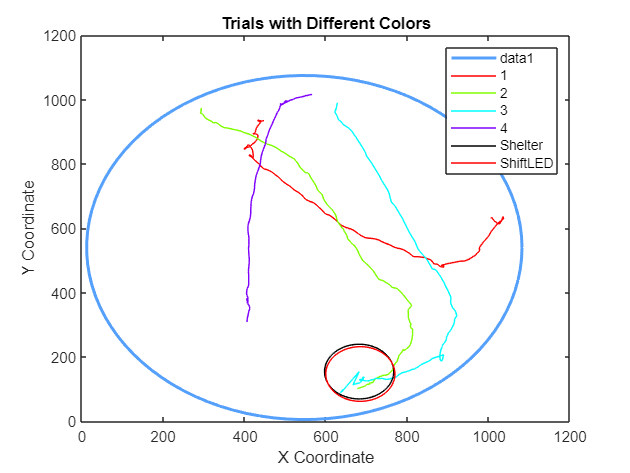

close all
numTrials = width(centre_xcorrected14s);  % Number of trials

% Generate a colormap with a range of distinct colors
colors = hsv(numTrials);  % hsv colormap provides a distinct color for each trial

figure
theta = linspace(0, 2*pi);

% Plot the platform
platform_x_circle = platform_r * cos(theta) + platform_x;
platform_y_circle = platform_r * sin(theta) + platform_y;
plot(platform_x_circle, platform_y_circle, 'color', "#55A0FB", 'linewidth', 2)
hold on

% Plot each trial with a unique color and label with column number
for i = 1:numTrials
    plot(centre_xcorrected14s(:,i), centre_ycorrected14s(:,i), 'Color', colors(i, :), 'DisplayName', sprintf('%d', i));
end

% Add shelter location to plot
x_shelter = shelter_r * cos(theta) + shelter_x;
y_shelter = shelter_r * sin(theta) + shelter_y;
plot(x_shelter, y_shelter, "black", 'DisplayName', 'Shelter')

% Add shiftLED location to plot

x_shiftLED = shiftLED_r * cos(theta) + shiftLED_x;
y_shiftLED = shiftLED_r * sin(theta) + shiftLED_y;
plot(x_shiftLED, y_shiftLED, "red", 'DisplayName', 'ShiftLED')

% Labels, title, and legend
xlabel('X Coordinate');
ylabel('Y Coordinate');
title('Trials with Different Colors');
legend;

hold off

### Trial Identifying information

% Define the prompt for each input
prompt = {'Enter Animal ID:', 'Enter Trial:', 'Enter Shift Condition:'};

% Define a title for the input dialog box
dlgtitle = 'Input Required';

% Define the dimensions of the input dialog box (optional)
dims = [1 35];

% Display the input dialog box and store the output
answer = inputdlg(prompt, dlgtitle, dims);

% Extract the individual answers and assign them to variables
AnimalID = answer{1};
Trial = answer{2};
ShiftCondition = answer{3};

## Save the entire workspace as a mat file

% Create the filename with underscores separating the variable values
filename = [AnimalID '_' Trial '_' ShiftCondition '.mat'];

% Save the MATLAB file with the generated filename
save(filename);

### Create tajectory position and speed plots with platform shelter and position when ultrasound is initiated

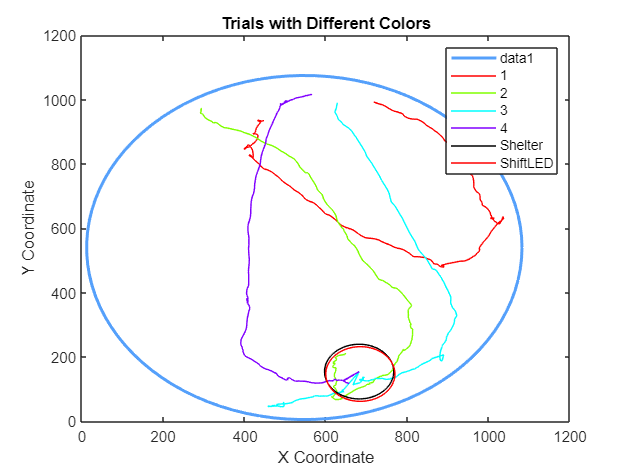

% 1
% for n = 1:length(ks)
% 
%     figure
%     xc_platform = platform_x;
%     yc_platform = platform_y;
%     platform_r = platform_r;

% 
%     theta = linspace(0,2*pi);
%     platform_x = platform_r*cos(theta) + xc_platform;
%     platform_y = platform_r*sin(theta) + yc_platform;
%     plot(platform_x,platform_y, "blue")
%     hold on
% 
%     xc_shelter = shelter_x;
%     yc_shelter = shelter_y;
%     r_shelter = shelter_r;
% 
%     % add shelter location to plot
%     theta = linspace(0,2*pi);
%     x_shelter = r_shelter*cos(theta) + xc_shelter;
%     y_shelter = r_shelter*sin(theta) + yc_shelter;
%     plot(x_shelter,y_shelter, "black")
%     hold on
% 
%     % add body position at ultrasound onset to plot
%     plot(centre_xcorrected9sec(bl+1,n), centre_ycorrected(bl+1,n),"bs", "MarkerSize", shelter_r,'LineWidth',1)
%     %plot(centre_x(bl+1,n), centre_y(bl+1,n),"bs", "MarkerSize", shelter_r,'LineWidth',1)
% 
%     hold on
% 
%     % scatter plot with signals
%     pointsize = 61;
%     x = centre_xcorrected9sec(:,n);
%     y = centre_ycorrected9sec(:,n);
% %     x = centre_x(:,n);
% %     y = centre_y(:,n);
%     z = speedmeterspersec(:,n);
%     xCoordinate = round(x);
%     yCoordiante = round(y);
%     scatter(xCoordinate, yCoordiante, pointsize, z,'filled')
%     colormap jet %winter %autumn
%     % Colour schemesusing winter for path integration, autumn for cued conflict
%     colorbar
% 
%     xlabel('x coordinate')
%     ylabel('y coordinate')
% 
% end

## **Visualizing raster plots for representative escapes**

Raster plots for normalized distance to shelter, speed (in m/sec) and head angle will be created for the selected escape specified by changing the number in the field box.

Not necessary to run unless you want to extract raster plots for specific example escapes.

% close all
%
% ndistance_escape = ndistance(:,1)
% imagesc(ERF_time,1:length(ks),ndistance_escape')
%
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('nDistance')
% colormap autumn %using winter for path integration and autmn for cued conflict update accordingly
% colorbar
% figure
%
% speed_escape = speedmpers(:,1)
% imagesc(ERF_time,1:length(ks),speed_escape')
%
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('Speed')
% colormap autumn %using winter for path integration and autmn for cued conflict update accordingly
% colorbar
% figure
%
% theta = [];
% for k = 1:length(ks)
%    theta(:,k) = event_X{k}.theta;
% end
%
% theta_escape = theta(:,1)
% imagesc(ERF_time,1:length(ks),theta_escape')
%
% xlabel('Time Relative to ultrasound onset (seconds)')
% ylabel('Theta')
% colormap autumn %using winter for path integration and autmn for cued conflict update accordingly
% colorbar
% figure

## Spatial heatmap of feature signals (optional)

Where do your feature signals rise and fall? The heatmap plot shows the spatial dynamics of your feature signals.

% feature_data = DLCdata.v_centre;
% close all
% % scatterplot
% pointsize = 33;
% scatter(DLCdata.nose_x, DLCdata.nose_y, pointsize, feature_data,'filled')
% colormap jet
% colorbar
% xlabel('nose_x coordinate')
% ylabel('nose_y coordinate')
% title ('Speed and Position heatmap')

## 2D histogram of body part location (optional)

Where was the animal during the test? The plot shows how the reported body part locations are distributed throughout the test arena as a form of 2D histogram and heatmap.

% % 2d histogram
% close all
% histogram2(DLCdata.nose_x ,DLCdata.nose_y,'NumBins',26);
% xlabel('nose_x');
% ylabel('nose_y');
% zlabel('Count');
% %% binscatter
% bins = 26;
% binscatter(DLCdata.nose_x,DLCdata.nose_y,bins);
% xlabel('nose_x coordinate')
% ylabel('nose_y coordinate')
% title ('Nose position heatmap')
% colormap jet
% %% binscatter
% bins = 31;
% binscatter(DLCdata.theta,DLCdata.v_centre,bins);
% xlabel ("Theta")
% ylabel('Speed')
% title ('Theta-Speed heatmap')
% colormap jet

## Save the identifying features of the test session

% AnimalID = inputdlg('Enter the Animal ID:','Sample', [1 50]);
% Sex = inputdlg('Enter the sex of the animal (M/F):','Sample', [1 50]);
% Strain = inputdlg('Enter the strain of the animal:','Sample', [1 50]);
% Genotype = inputdlg('Enter the genotype of the animal (WT/HET/Homo):','Sample', [1 50]);
% Session = inputdlg('Enter the test session number:','Sample', [1 50]);
% Condition = inputdlg('Enter the condition (e.g.Tox vs Control):','Sample', [1 50]);

## Save trial wise data as class object "Trial"

% load('C:\Users\kandy\OneDrive - University of Toronto\UofT\Git Repositories\Path Integration\TrialArrayTox.mat')
% % Uncomment this line when you are creating the initial array
% % TrialArray =Trial.empty();
%
% [rownum colnum] = size(TrialArray)
%
% for i = 1:k
%         TrialArray(1,i+colnum) = Trial();
%         TrialArray(1,i+colnum).Trialnumber = i;
%
%         TrialArray(1,i+colnum).AnimalID = AnimalID;
%         TrialArray(1,i+colnum).Sex = Sex;
%         TrialArray(1,i+colnum).Strain = Strain;
%         TrialArray(1,i+colnum).Genotype = Genotype;
%         TrialArray(1,i+colnum).Session = Session;
%         TrialArray(1,i+colnum).Condition = Condition;
%
%         TrialArray(1,i+colnum).nDistance = distancefinal(:,i);
%         TrialArray(1,i+colnum).Speed = speedcorrected(:,i);
%         TrialArray(1,i+colnum).Theta = thetacorrected(:,i);
%
%         TrialArray(1,i+colnum).nDistance_binned = binnedndistance(:,i);
%         TrialArray(1,i+colnum).Speed_binned = binnedspeed(:,i);
%         TrialArray(1,i+colnum).Theta_binned = binnedtheta (:,i);
%
%         TrialArray(1,i+colnum).Accuracy = escape.accuracy(:,i);
%         TrialArray(1,i+colnum).Duration = escape.duration(:,i);
%         TrialArray(1,i+colnum).Distance = escape.distance(:,i);
%         TrialArray(1,i+colnum).Linearity = escape.linearity(:,i);
%         TrialArray(1,i+colnum).Max_Speed = escape.max_speed(:,i);
%         TrialArray(1,i+colnum).Max_Elapsed = escape.max_elapsed(:,i);
%         TrialArray(1,i+colnum).Max_Theta = escape.max_theta(:,i);
%
%         i = i +1
% end
%
% save('C:\Users\kandy\OneDrive - University of Toronto\UofT\Git Repositories\Path Integration\TrialArrayTox.mat', 'TrialArray')